
% IMPORT "BridgeMatlabExcel" 

clear all
warndlg("SONO SICURO DI AVER AGGIORNATO L'EXCEL NELLA DIRECTORY");
file = 'SIMULAZIONE_DATI_UTENTI_MATLAB.xlsx';


Google = readtable(file, 'Sheet', 'Google')

Google = 31×13 table
    SOGGETTO    TempoGS1    IterGS1    TempoGS2    IterGS2    TempoGS3    IterGS3    TempoGR1    IterGR1    TempoGR2    IterGR2    TempoGR3    IterGR3
    ________    ________    _______    ________    _______    ________    _______    ________    _______    ________    _______    ________    _______

        1        102.4        19        107.9        19        112.1        19        121.7        19        168.9        24        171.7        24   
        2        152.9        24        142.4        24        117.4        20     

Vosk = readtable(file, 'Sheet', 'Vosk')

Vosk = 31×13 table
    SOGGETTO    TempoVS1    IterVS1    TempoVS2    IterVS2    TempoVS3    IterVS3    TempoVR1    IterVR1    TempoVR2    IterVR2    TempoVR3    IterVR3
    ________    ________    _______    ________    _______    ________    _______    ________    _______    ________    _______    ________    _______

        1         72.8        12         57.7        11         68.8        14         95.5        15         98.4        17         74.5        12   
        2          124        21         88.1        15         77.8        14       


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CONVERTING THE SINGLE TIMES AND ITERATIONS IN ARRAYS


timesGS1 = Google.TempoGS1;
timesGS2 = Google.TempoGS2;
timesGS3 = Google.TempoGS3;

timesGR1 = Google.TempoGR1;
timesGR2 = Google.TempoGR2;
timesGR3 = Google.TempoGR3;

timesVS1 = Vosk.TempoVS1;
timesVS2 = Vosk.TempoVS2;
timesVS3 = Vosk.TempoVS3;

timesVR1 = Vosk.TempoVR1;
timesVR2 = Vosk.TempoVR2;
timesVR3 = Vosk.TempoVR3;


iterGS1 = Google.IterGS1;
iterGS2 = Google.IterGS2;
iterGS3 = Google.IterGS3;

iterGR1 = Google.IterGR1;
iterGR2 = Google.IterGR2;
iterGR3 = Google.IterGR3;

iterVS1 = Vosk.IterVS1;
iterVS2 = Vosk.IterVS2;
iterVS3 = Vosk.IterVS3;

iterVR1 = Vosk.IterVR1;
iterVR2 = Vosk.IterVR2;
iterVR3 = Vosk.IterVR3;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% REMOVING ALL THE NAN AND ZEROS ELEMENT 

timesGS1 = depurate(timesGS1);
timesGS2 = depurate(timesGS2);
timesGS3 = depurate(timesGS3);

timesGR1 = depurate(timesGR1);
timesGR2 = depurate(timesGR2);
timesGR3 = depurate(timesGR3);

timesVS1 = depurate(timesVS1);
timesVS2 = depurate(timesVS2);
timesVS3 = depurate(timesVS3);

timesVR1 = depurate(timesVR1);
timesVR2 = depurate(timesVR2);
timesVR3 = depurate(timesVR3);

iterGS1 = depurate(iterGS1);
iterGS2 = depurate(iterGS2);
iterGS3 = depurate(iterGS3);

iterGR1 = depurate(iterGR1);
iterGR2 = depurate(iterGR2);
iterGR3 = depurate(iterGR3);

iterVS1 = depurate(iterVS1);
iterVS2 = depurate(iterVS2);
iterVS3 = depurate(iterVS3);

iterVR1 = depurate(iterVR1);
iterVR2 = depurate(iterVR2);
iterVR3 = depurate(iterVR3);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CREATING THE TOTAL VECTORS OF TIMES AND ITERATIONS


timesGS = [timesGS1; timesGS2; timesGS3];
timesGR = [timesGR1; timesGR2; timesGR3];
timesVS = [timesVS1; timesVS2; timesVS3];
timesVR = [timesVR1; timesVR2; timesVR3];

iterGS = [iterGS1; iterGS2; iterGS3];
iterGR = [iterGR1; iterGR2; iterGR3];
iterVS = [iterVS1; iterVS2; iterVS3];
iterVR = [iterVR1; iterVR2; iterVR3];







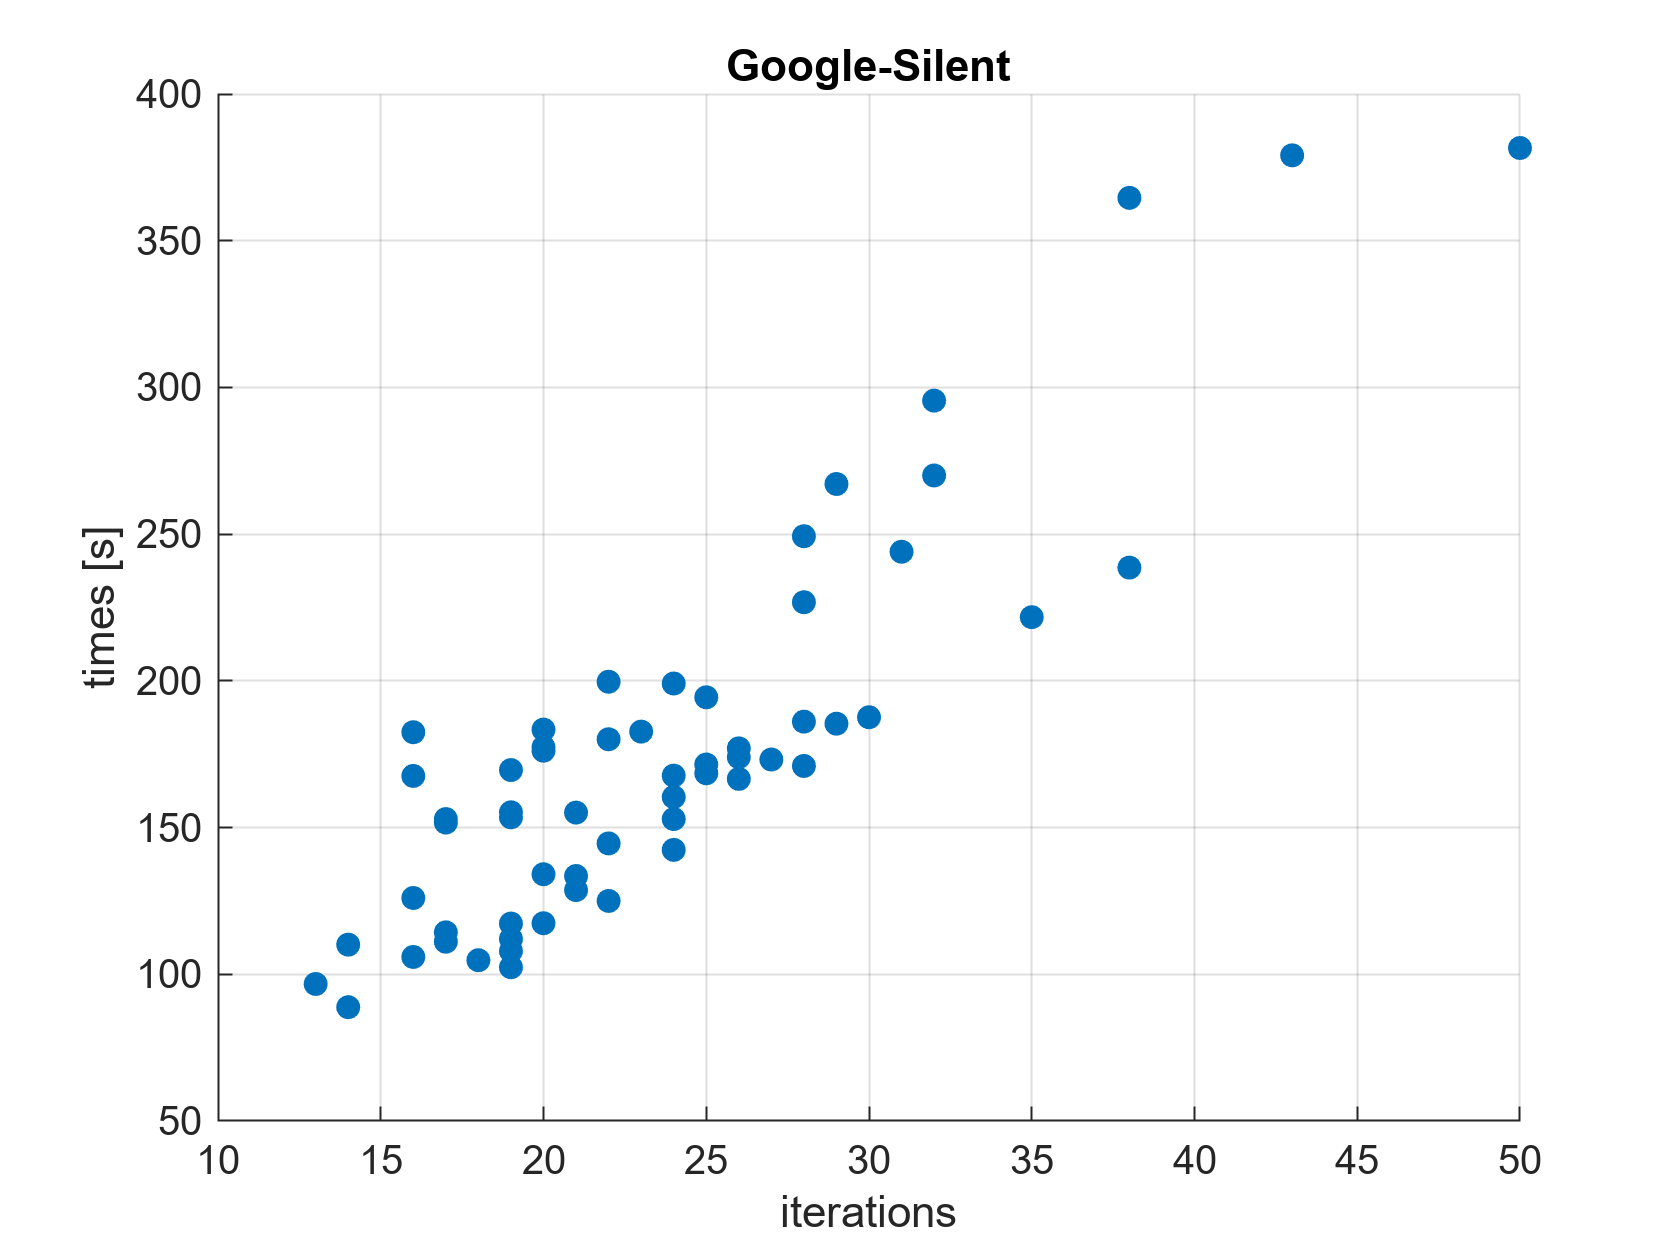

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% CREATING SCATTERS 



figure
scatter(iterGS, timesGS, 'filled')
title('Google-Silent')
xlabel('iterations')
ylabel('times [s]')
grid on

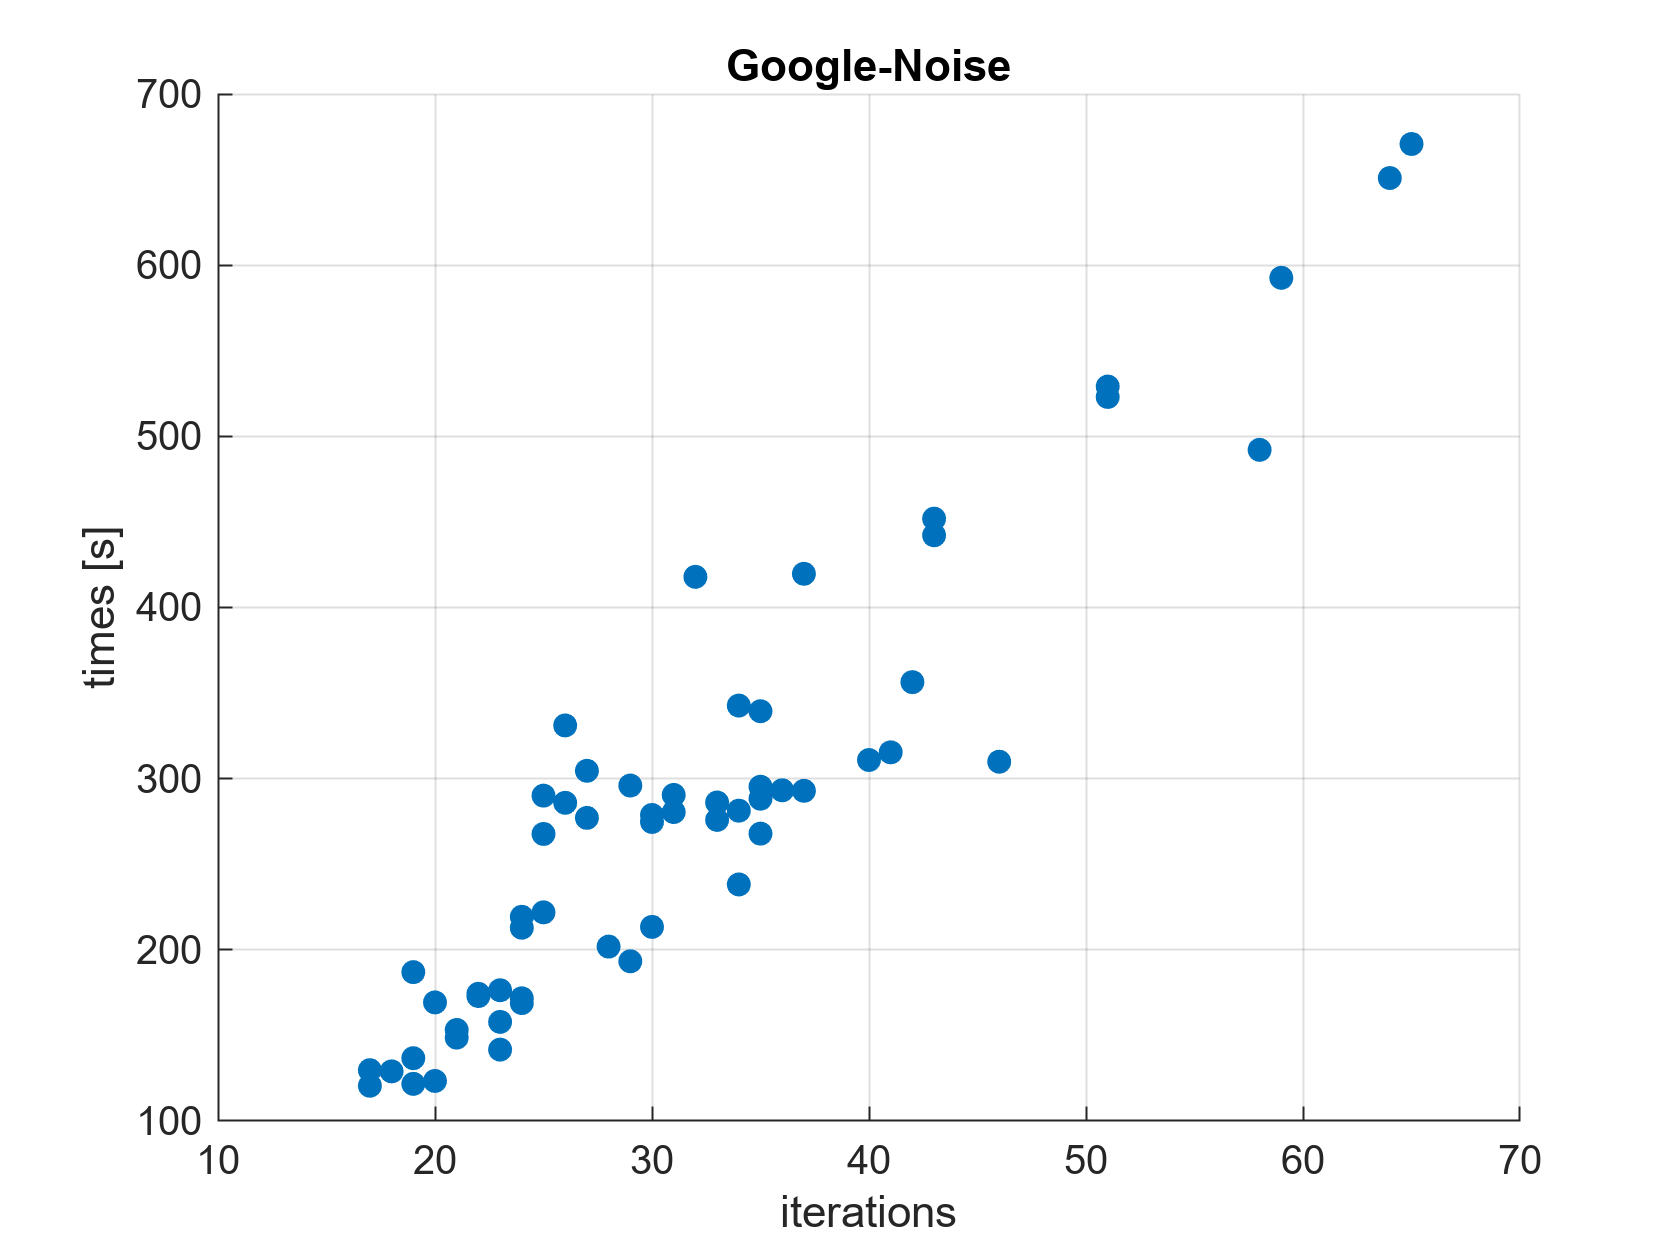


figure
scatter(iterGR, timesGR, 'filled')
title('Google-Noise')
xlabel('iterations')
ylabel('times [s]')
grid on

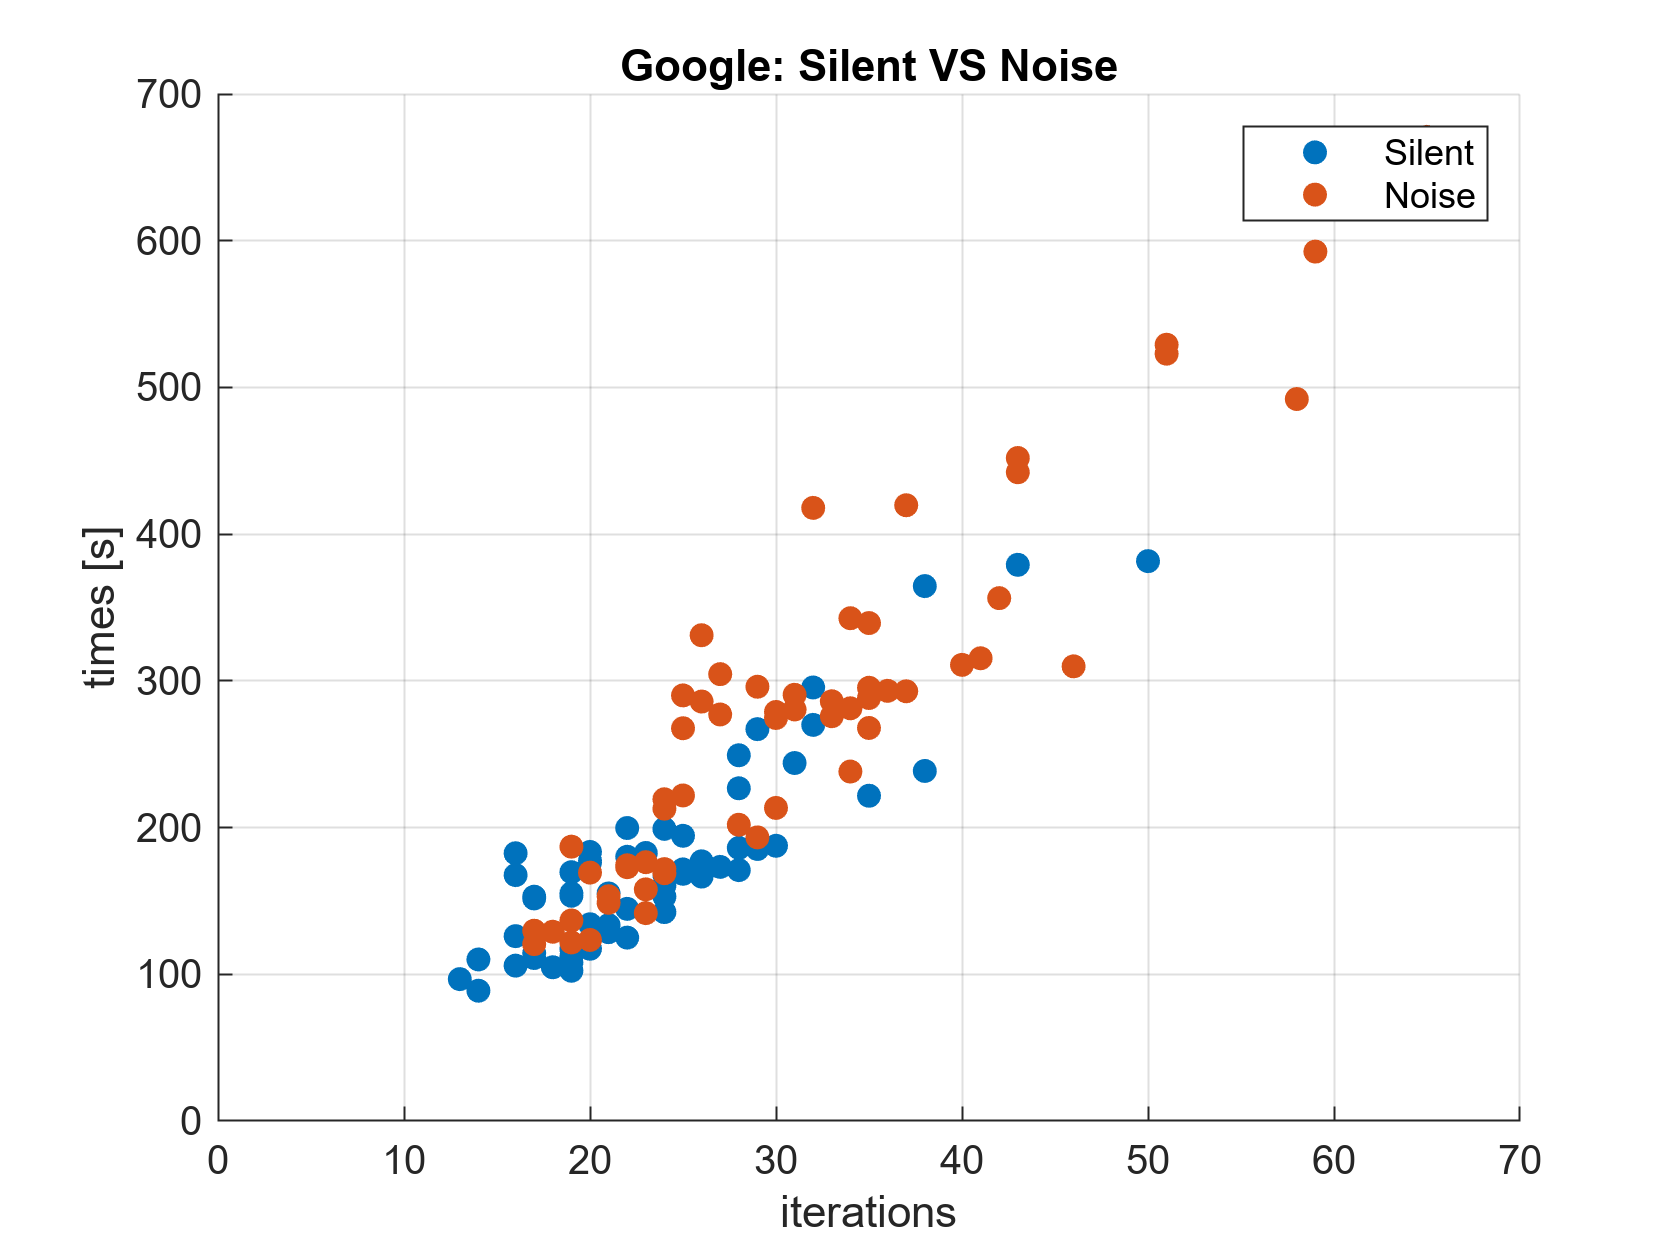


figure
scatter(iterGS, timesGS, 'filled')
hold on
scatter(iterGR, timesGR, 'filled')
title('Google: Silent VS Noise')
xlabel('iterations')
ylabel('times [s]')
legend('Silent','Noise')
xlim([0 70])
ylim([0 700])
grid on

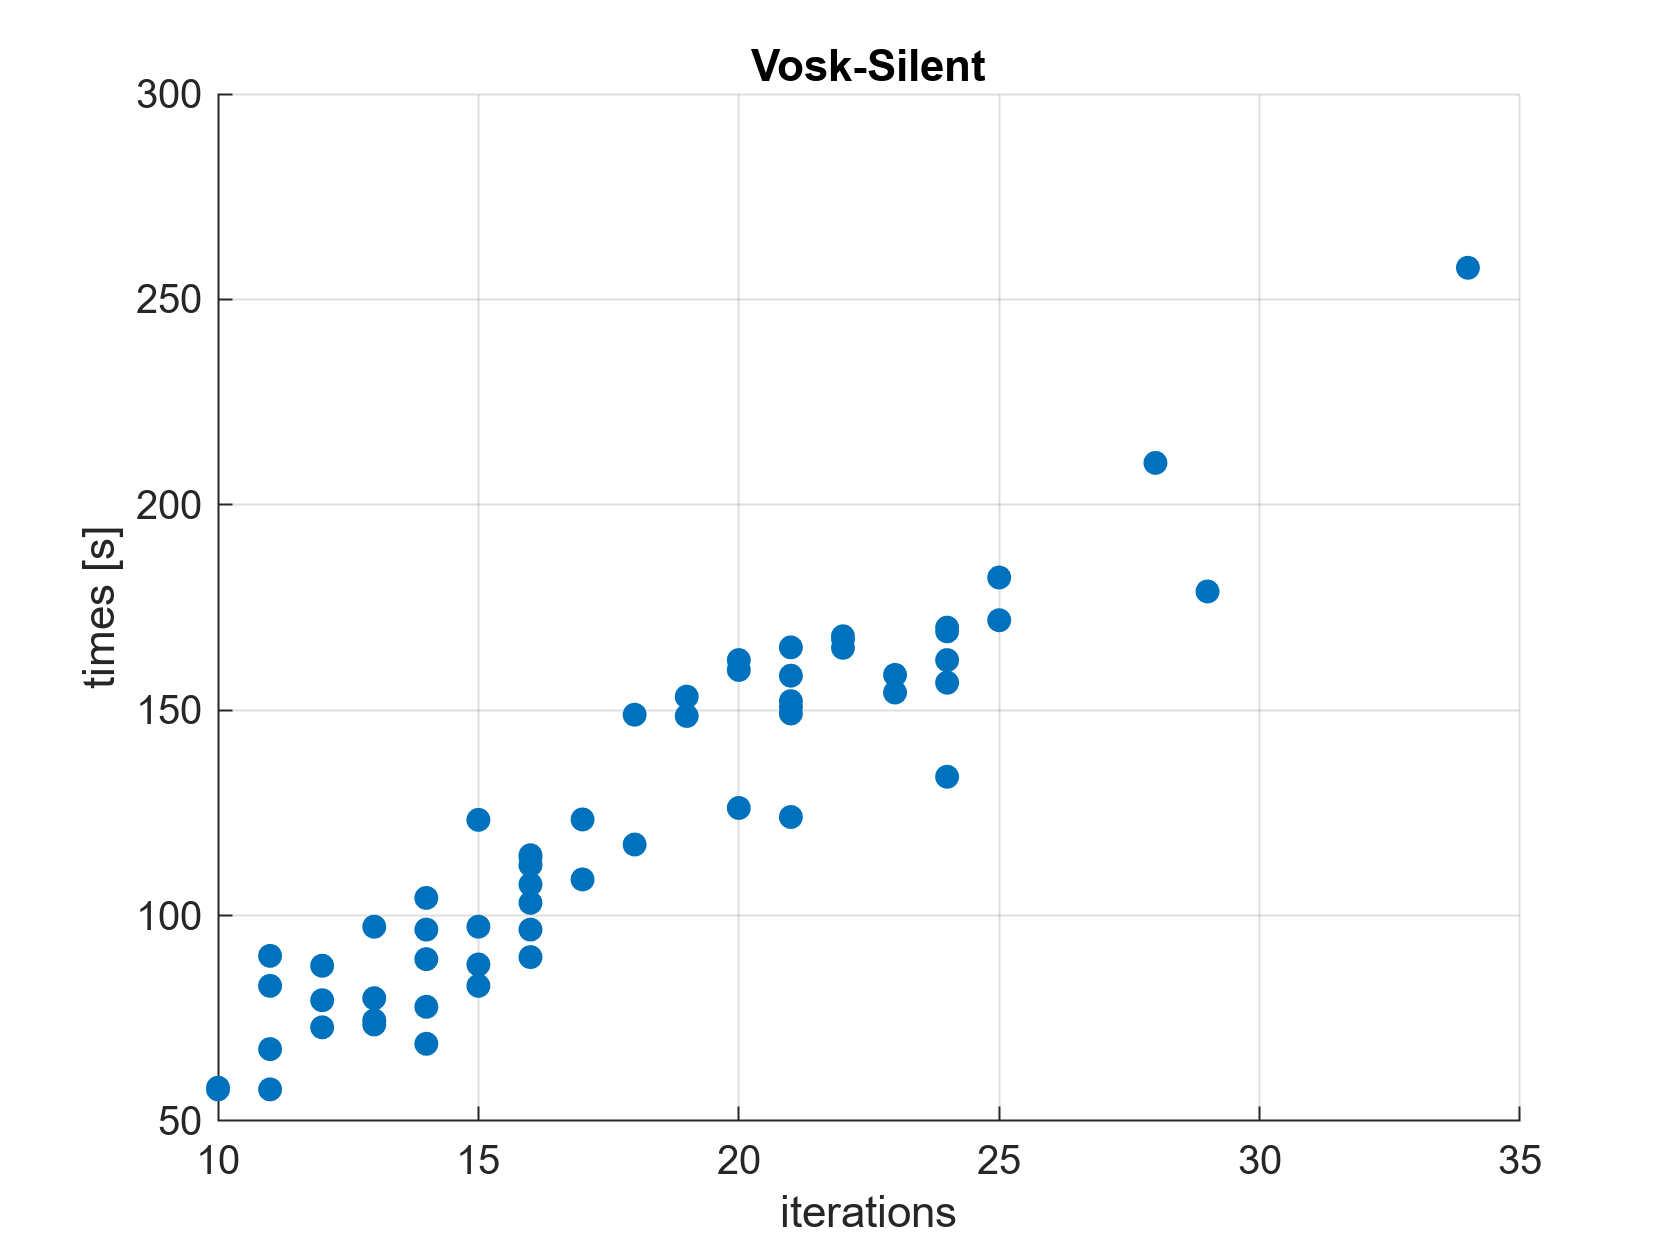


figure
scatter(iterVS, timesVS, 'filled')
title('Vosk-Silent')
xlabel('iterations')
ylabel('times [s]')


grid on

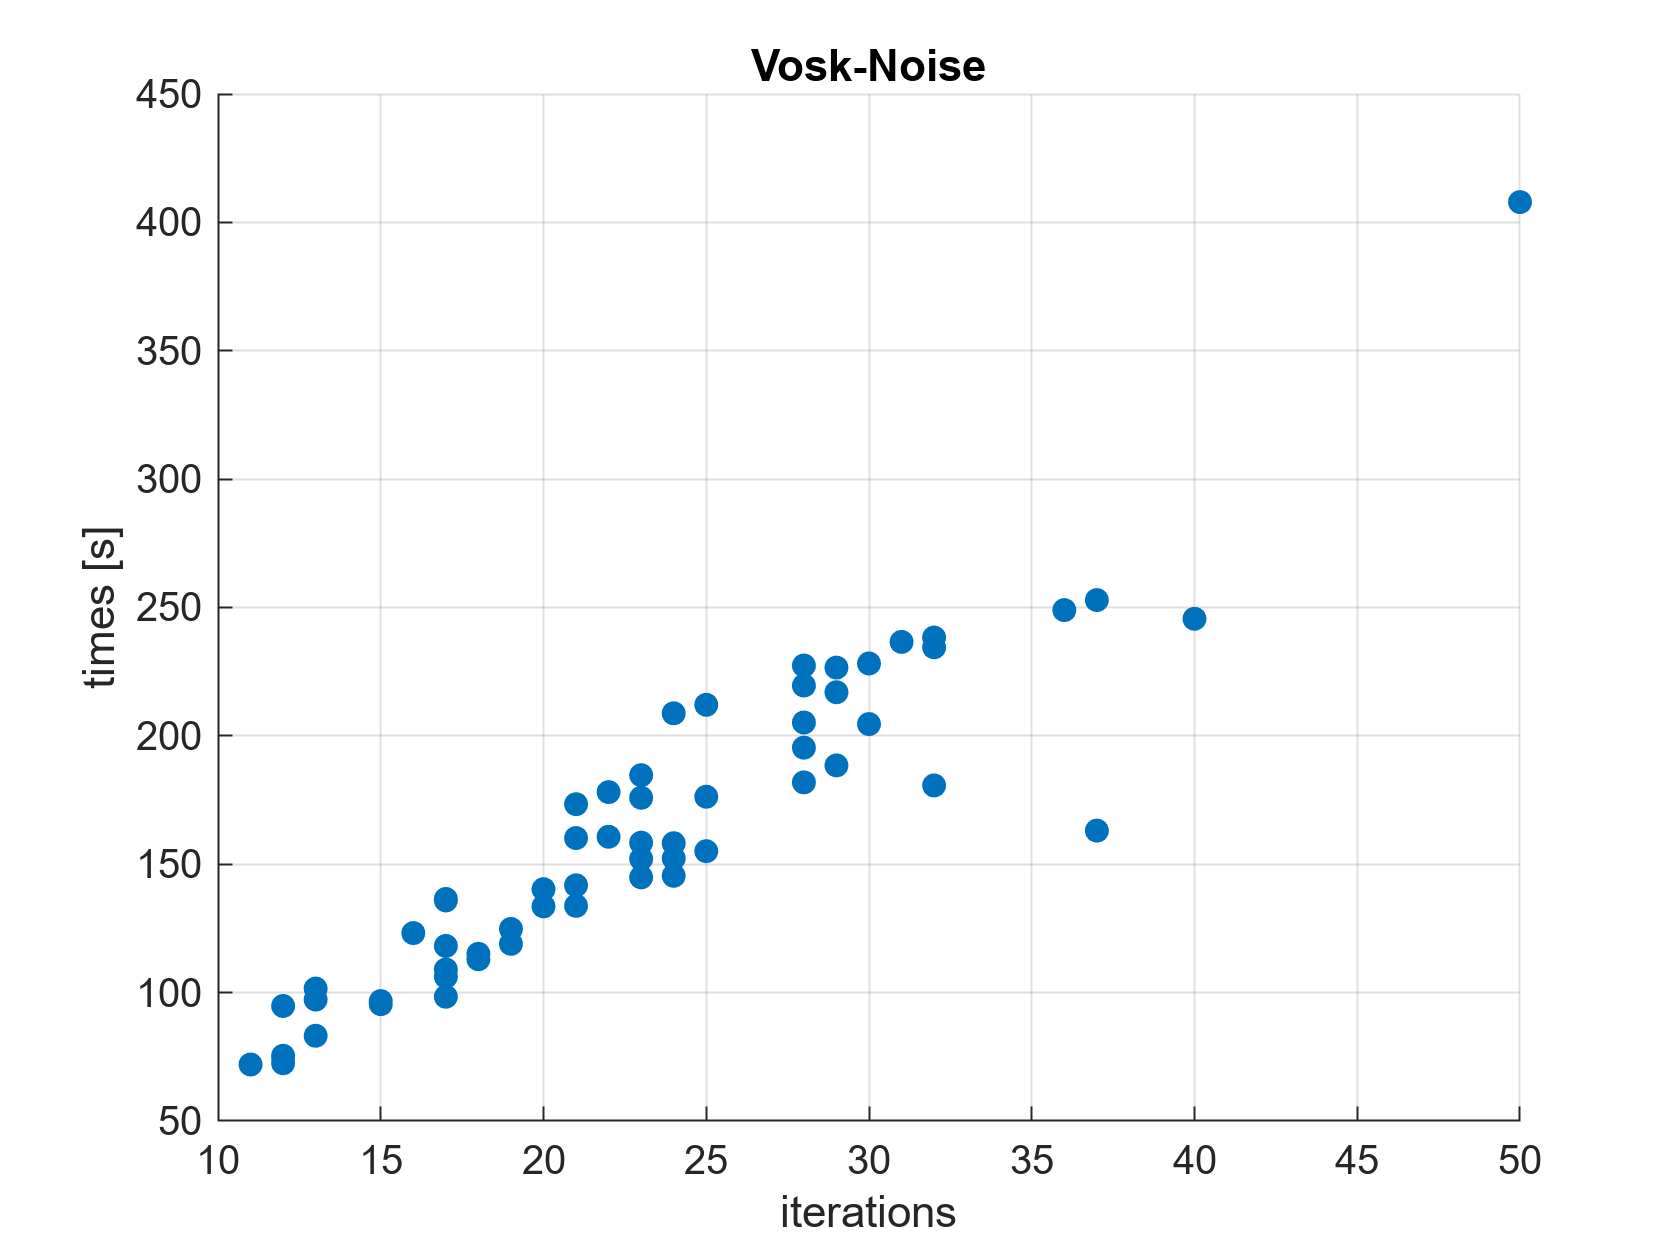



figure
scatter(iterVR, timesVR, 'filled')
title('Vosk-Noise')
xlabel('iterations')
ylabel('times [s]')
grid on

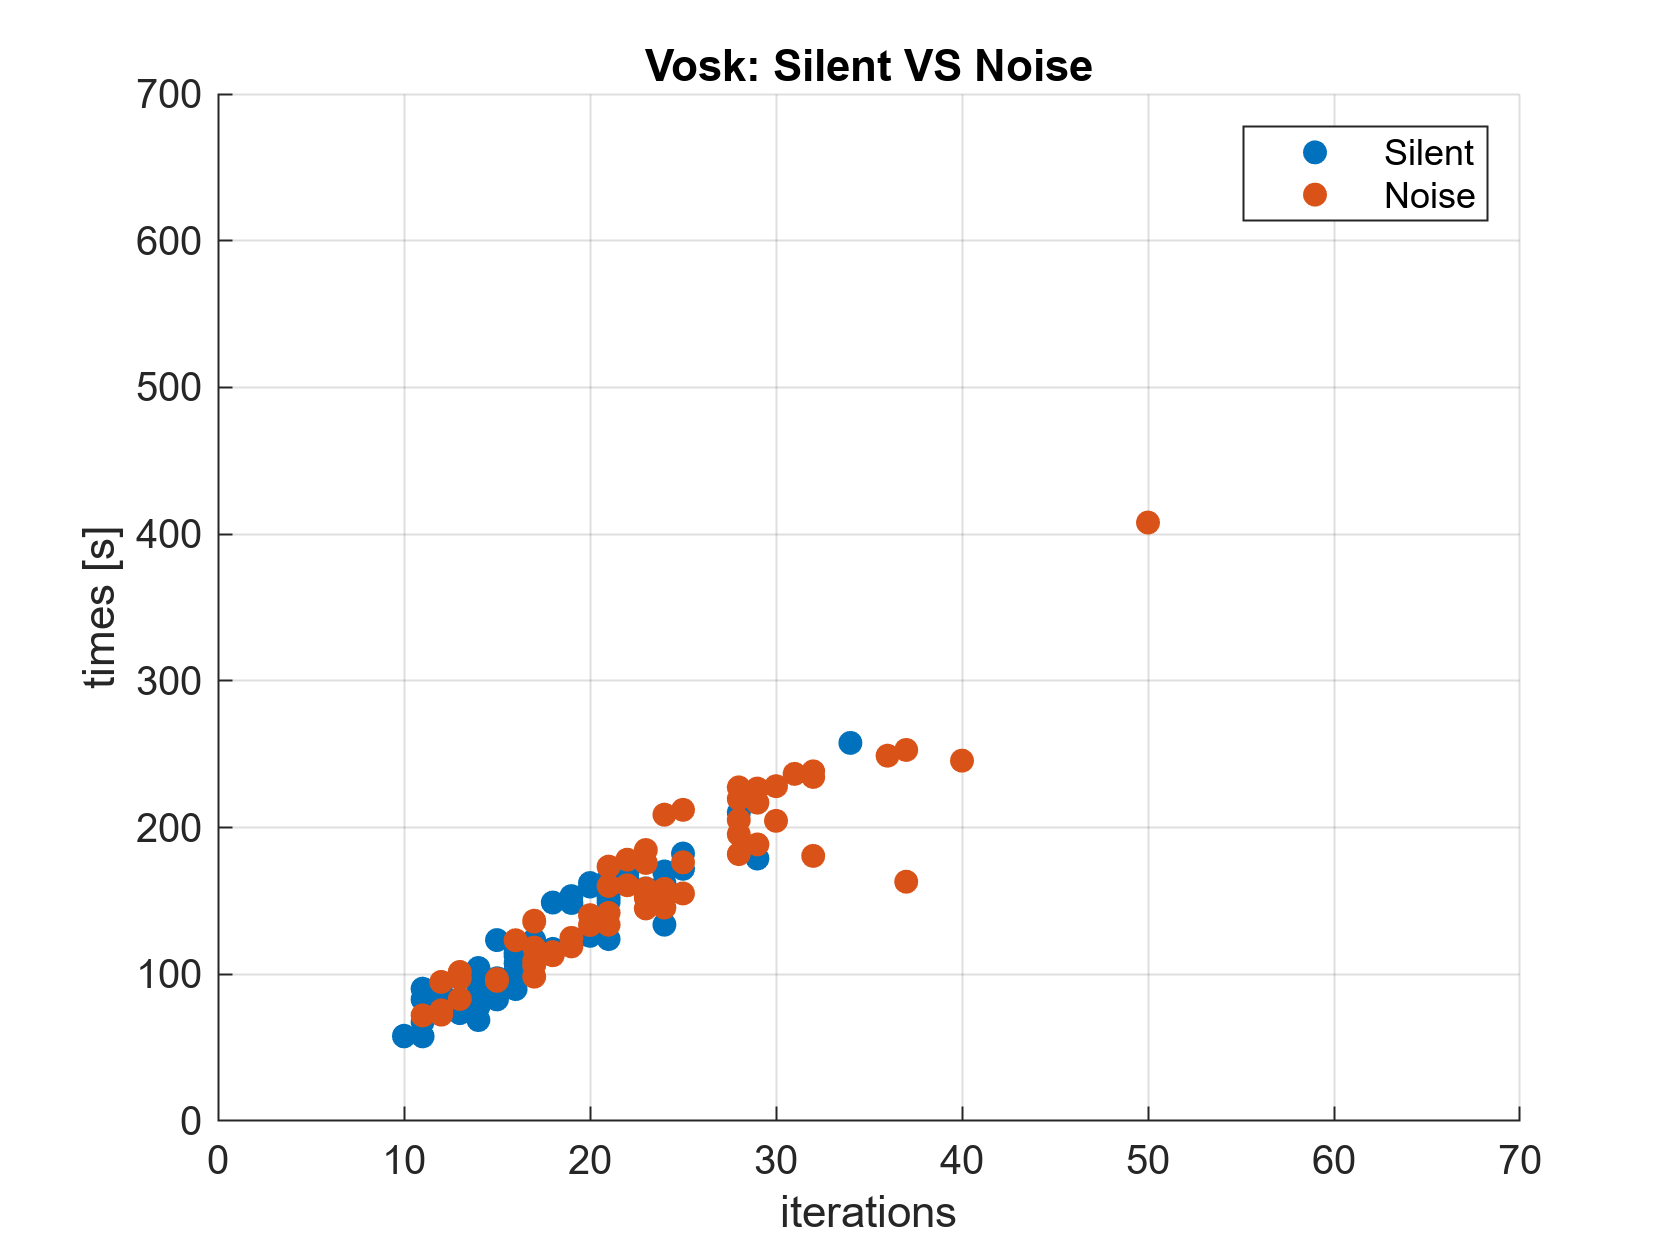



figure
scatter(iterVS, timesVS, 'filled')
hold on
scatter(iterVR, timesVR, 'filled')
title('Vosk: Silent VS Noise')
xlabel('iterations')
ylabel('times [s]')
legend('Silent','Noise')
xlim([0 70])
ylim([0 700])
grid on

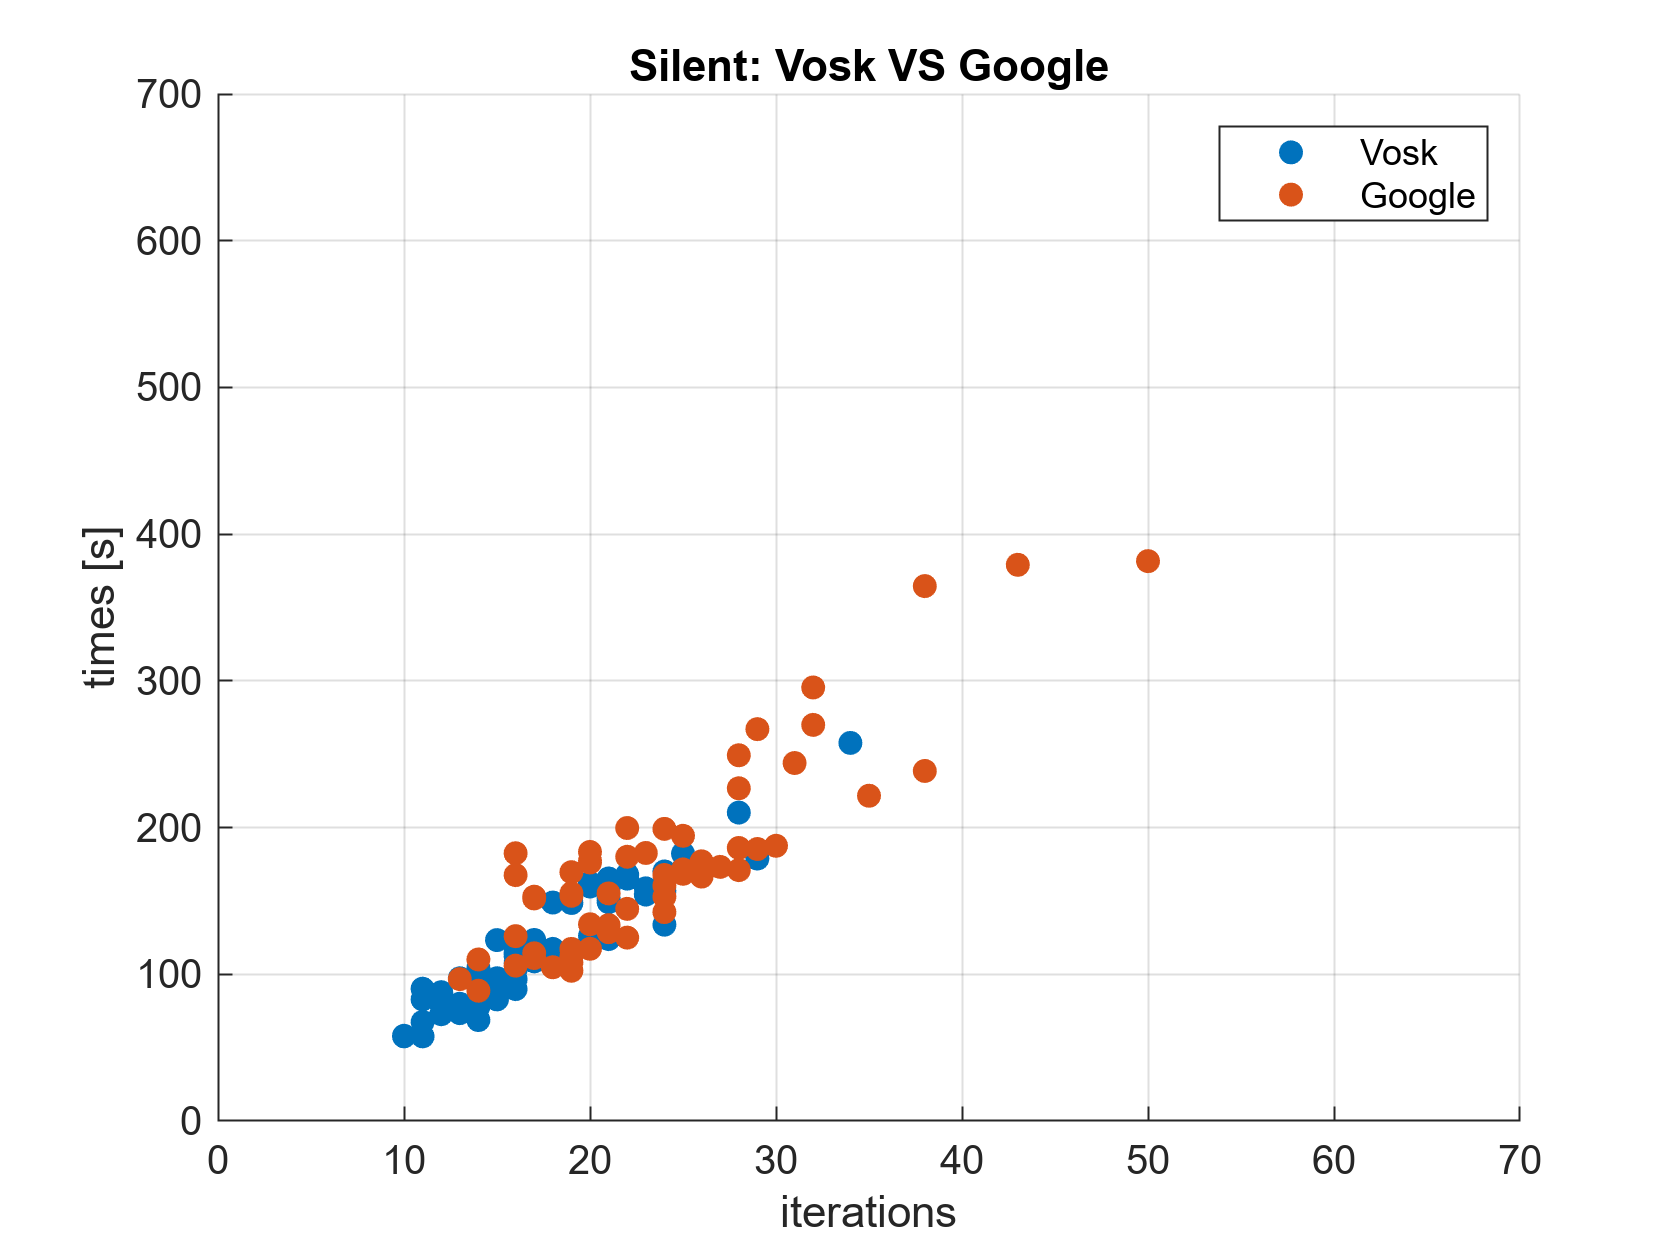

figure
scatter(iterVS, timesVS, 'filled')
hold on
scatter(iterGS, timesGS, 'filled')
title('Silent: Vosk VS Google')
xlabel('iterations')
ylabel('times [s]')
legend('Vosk','Google')
xlim([0 70])
ylim([0 700])
grid on

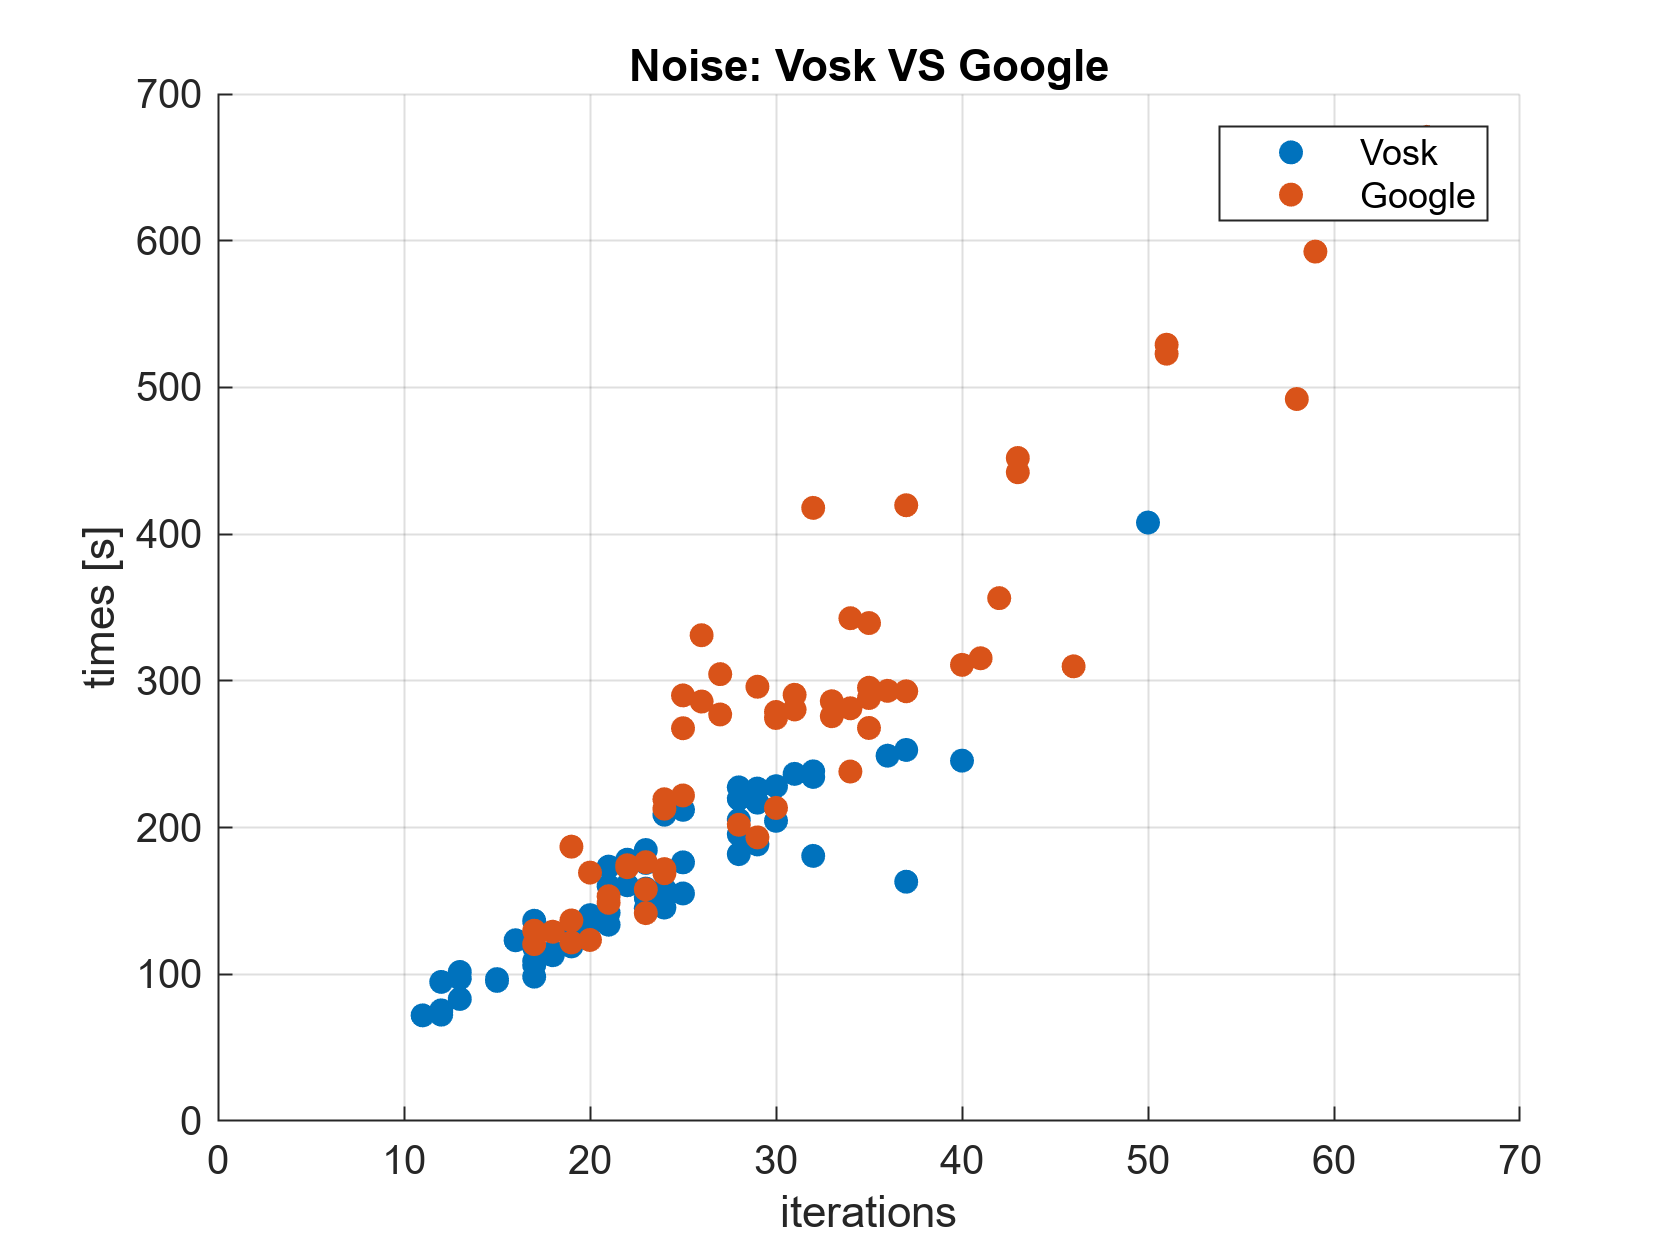

figure
scatter(iterVR, timesVR, 'filled')
hold on
scatter(iterGR, timesGR, 'filled')
title('Noise: Vosk VS Google')
xlabel('iterations')
ylabel('times [s]')
legend('Vosk','Google')
xlim([0 70])
ylim([0 700])
grid on

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% TESTING IF DATA ARE NORMAL DISTRIBUTED 

[h, p] =lillietest(timesGS)

h = 1

p = 1.0000e-03

[h, p] =lillietest(timesGR)

h = 1

p = 1.0000e-03

[h, p] =lillietest(timesVS)

h = 1

p = 0.0190

[h, p] =lillietest(timesVR)

h = 0

p = 0.5000


[h, p] =lillietest(iterGS)

h = 1

p = 0.0273

[h, p] =lillietest(iterGR)

h = 1

p = 0.0070

[h, p] =lillietest(iterVS)

h = 1

p = 0.0052

[h, p] =lillietest(iterVR)

h = 0

p = 0.2611

[h p] = lillietest([timesVR; timesVS;])

h = 0

p = 0.2245

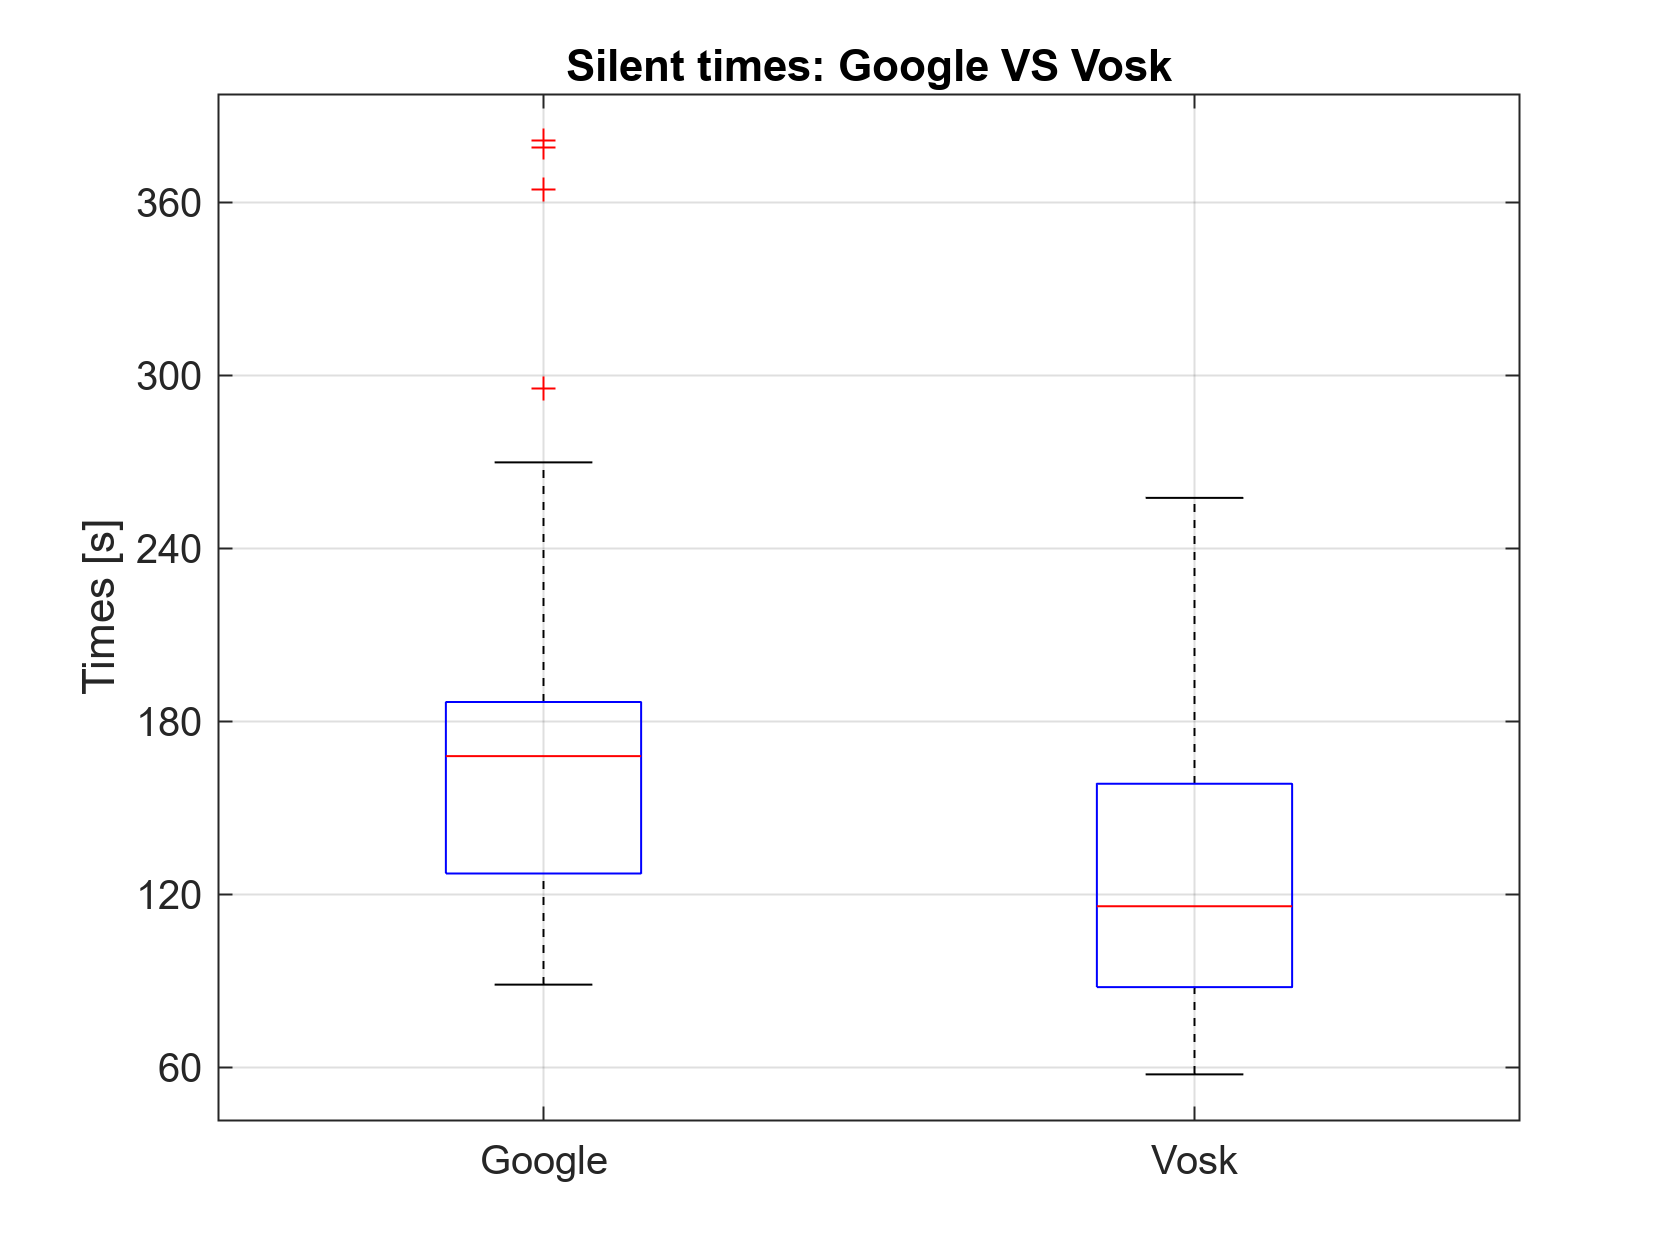

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CREATING BOXPLOTS 

figure
boxplot([timesGS, timesVS], Labels={'Google','Vosk'})
title('Silent times: Google VS Vosk')
ylabel('Times [s]')
yticks(0:60:420)
grid on

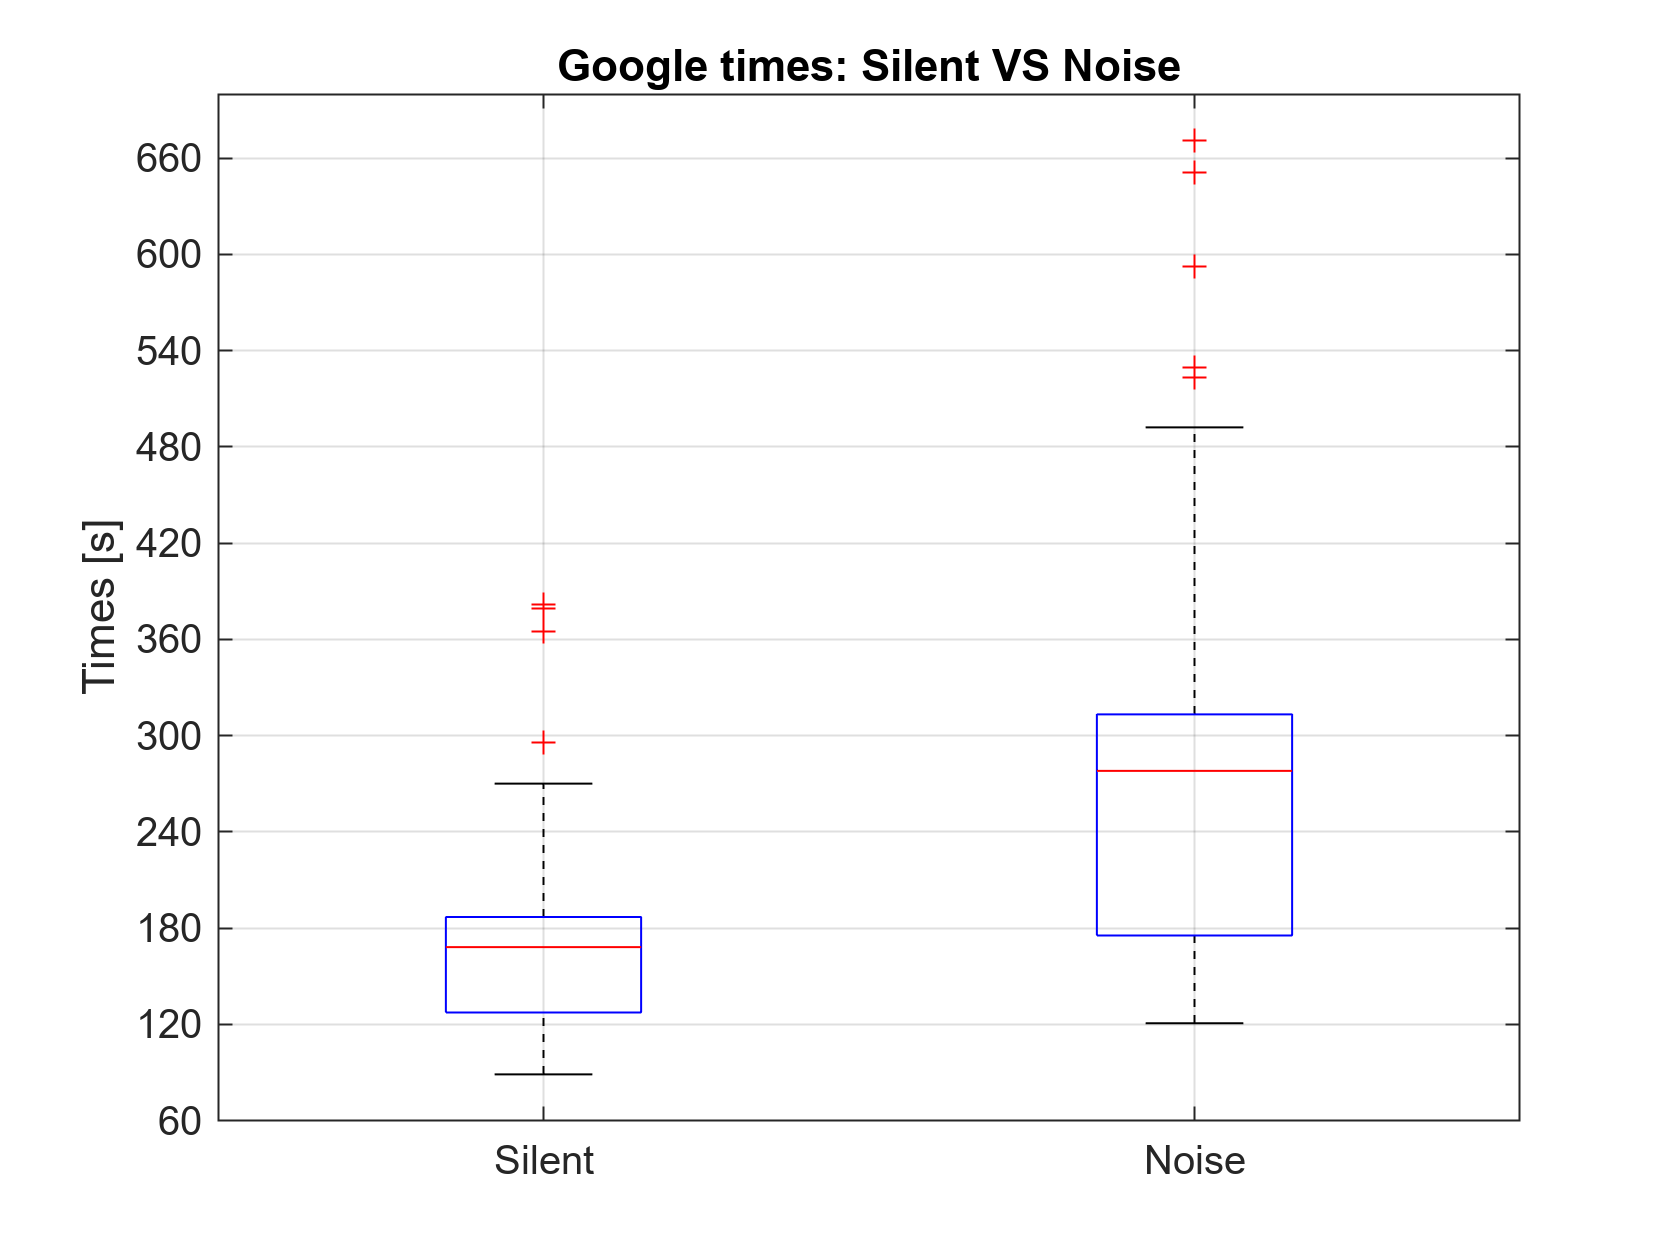


figure
boxplot([timesGS, timesGR], Labels={'Silent','Noise'})
title('Google times: Silent VS Noise')
ylabel('Times [s]')
yticks(0:60:700)
grid on

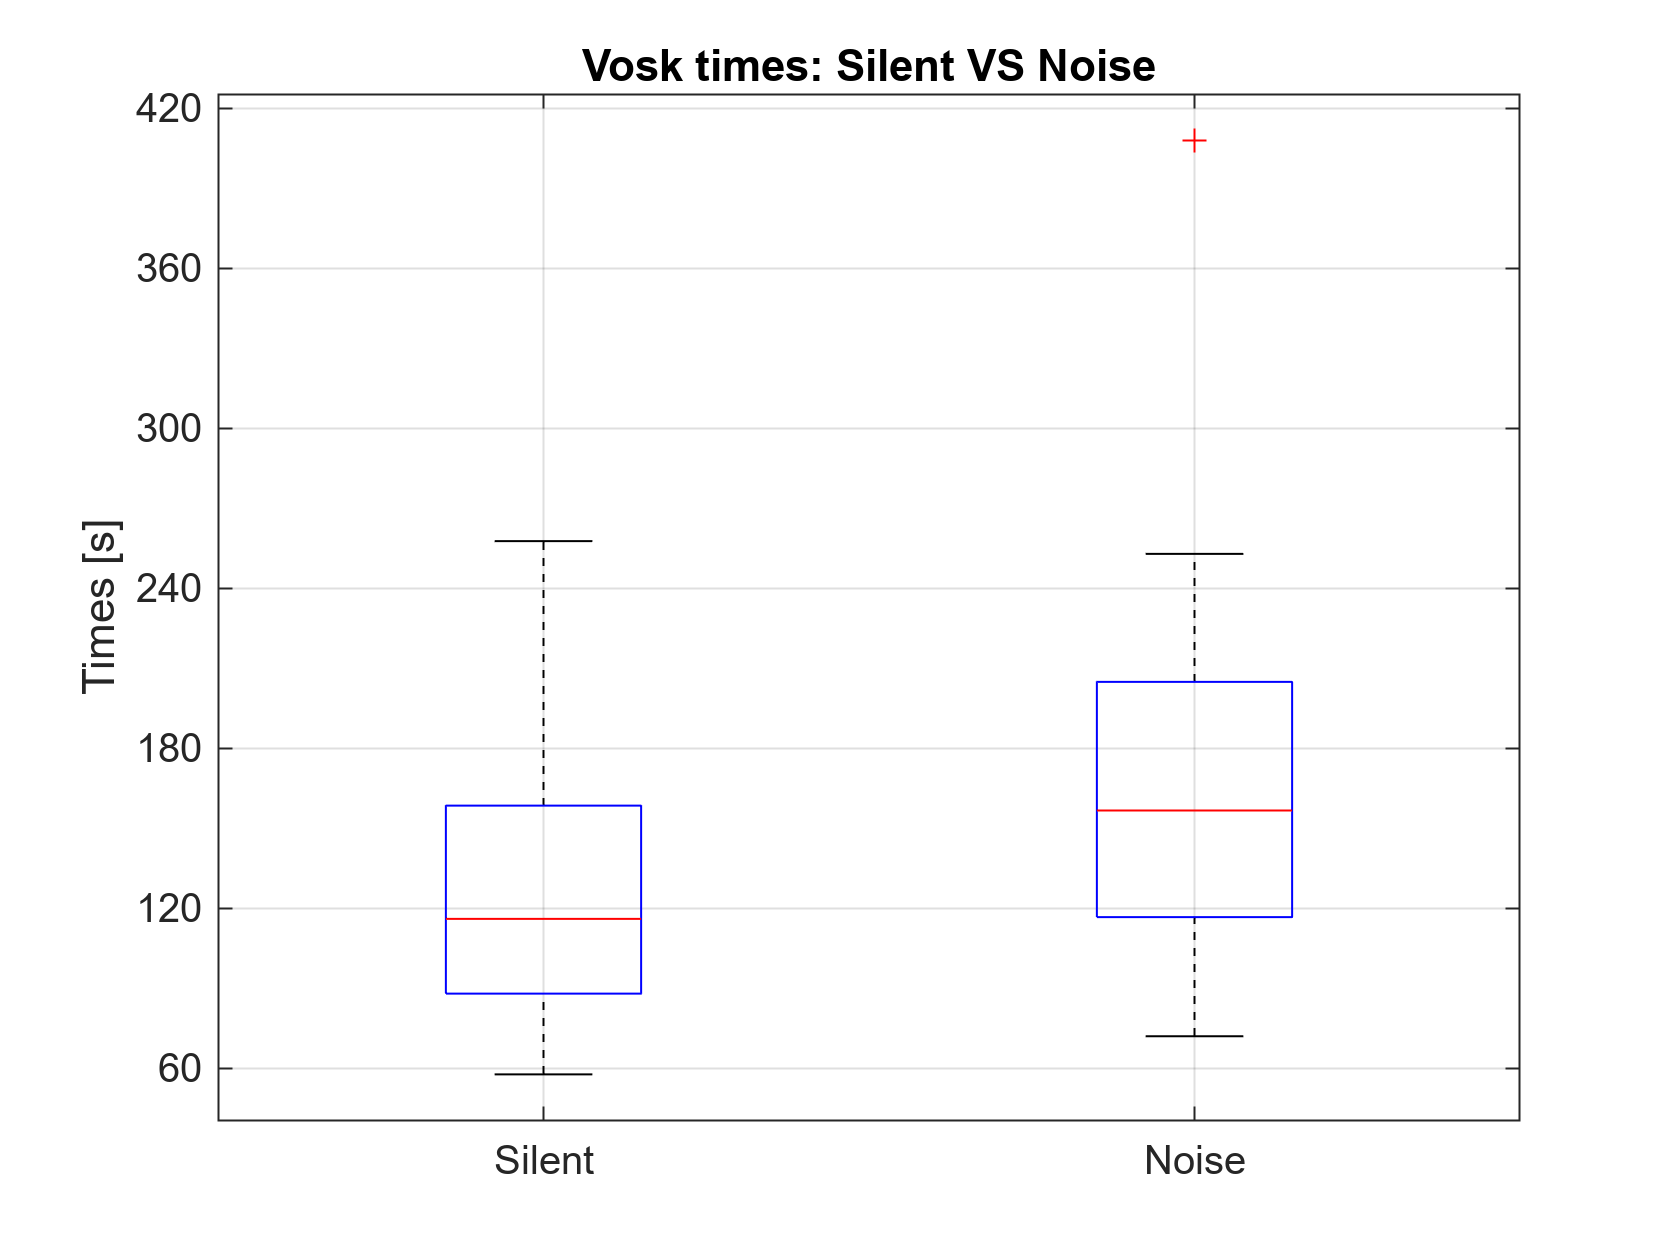

figure
boxplot([timesVS, timesVR], Labels={'Silent','Noise'})
title('Vosk times: Silent VS Noise')
ylabel('Times [s]')
yticks(0:60:700)
grid on

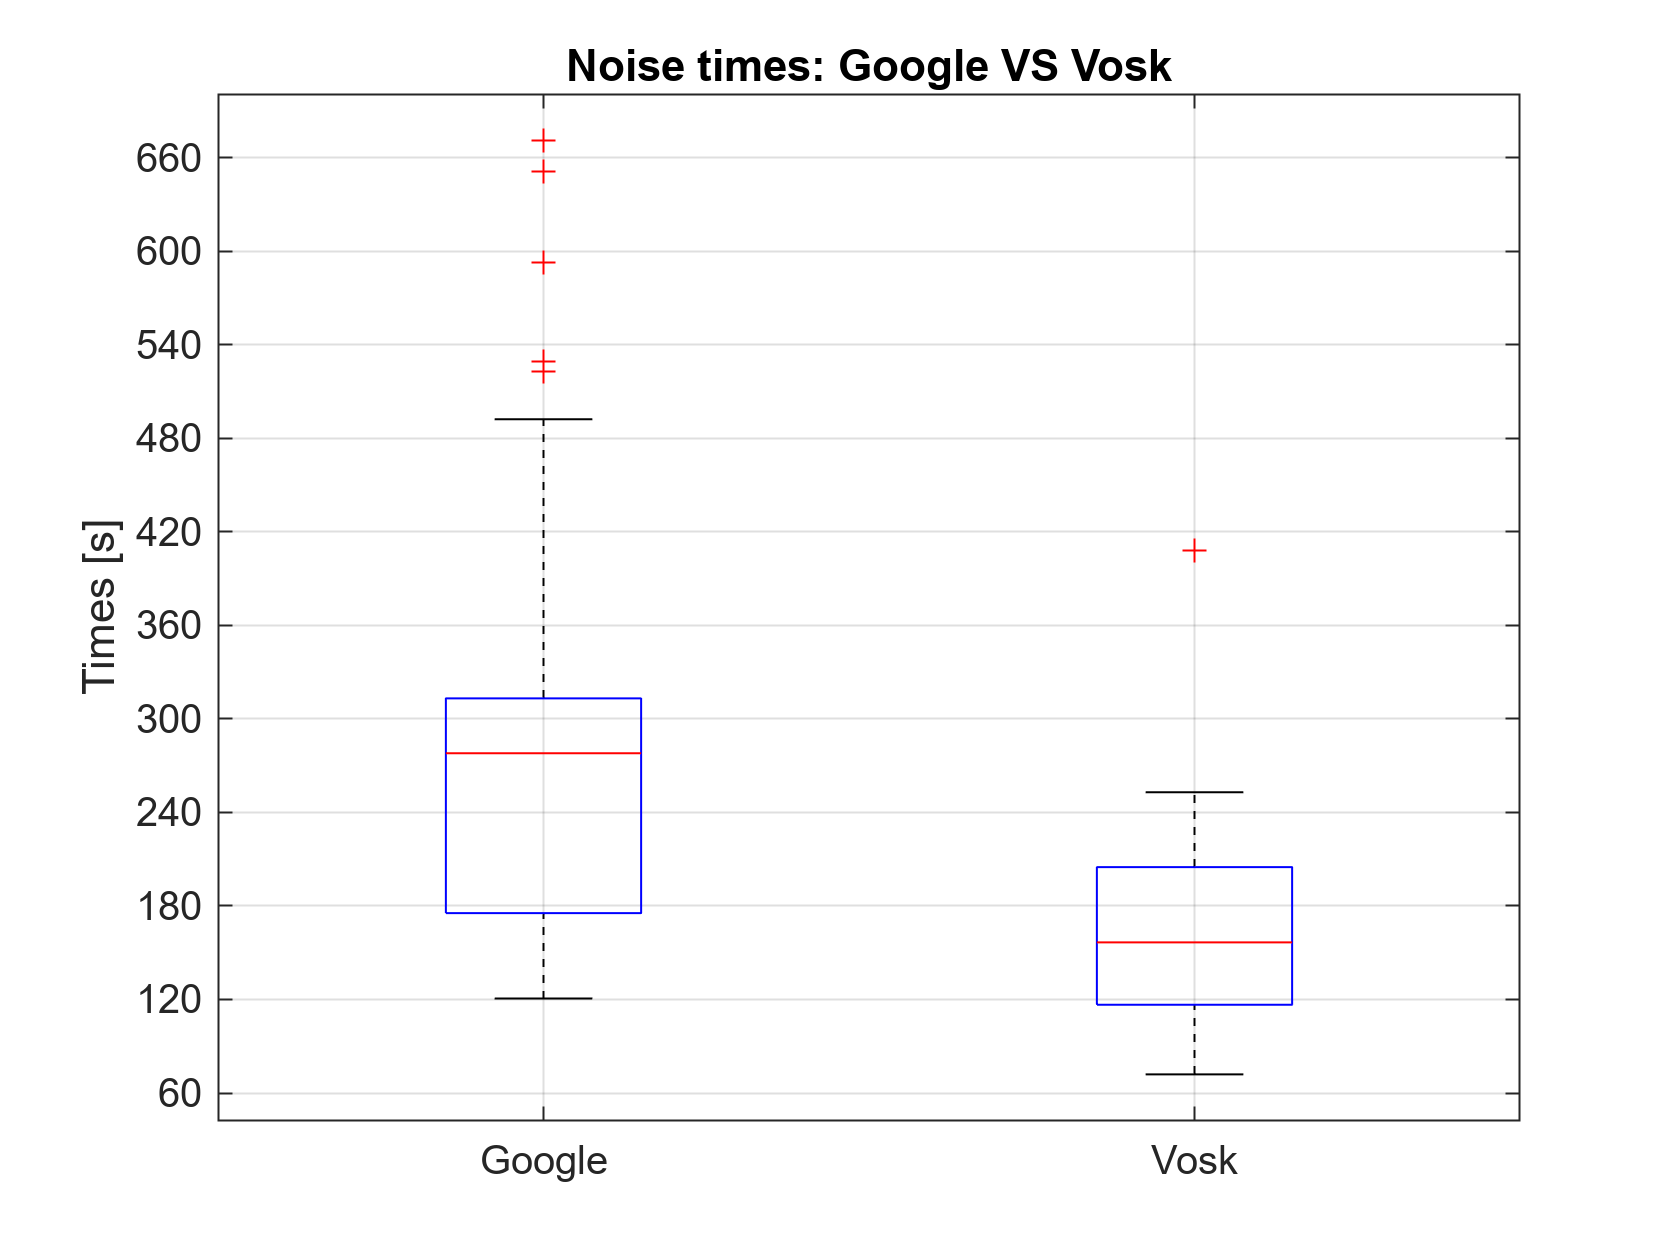



figure
boxplot([timesGR, timesVR], Labels={'Google','Vosk'})
title('Noise times: Google VS Vosk')
ylabel('Times [s]')
yticks(0:60:700)
grid on

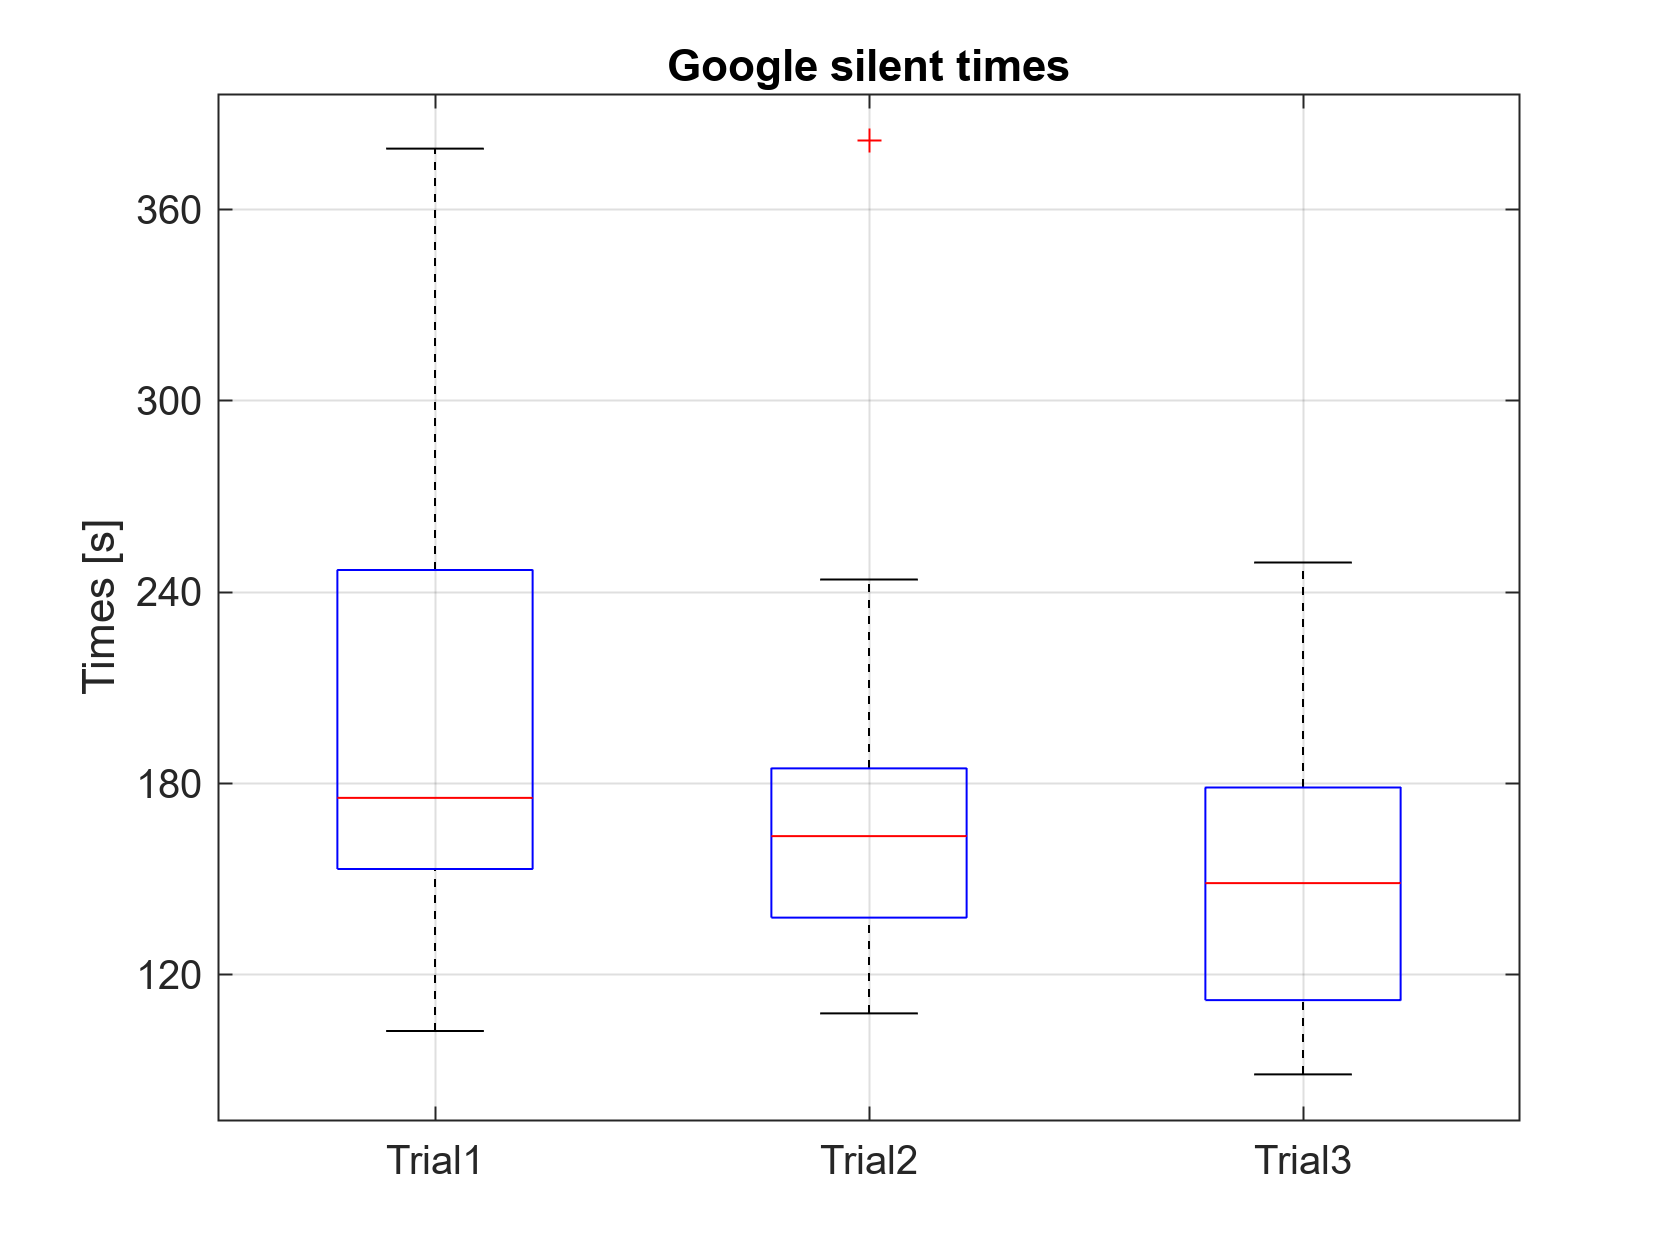

figure
boxplot([timesGS1, timesGS2, timesGS3], Labels={'Trial1','Trial2','Trial3'})
title('Google silent times')
ylabel('Times [s]')
yticks(0:60:700)
grid on

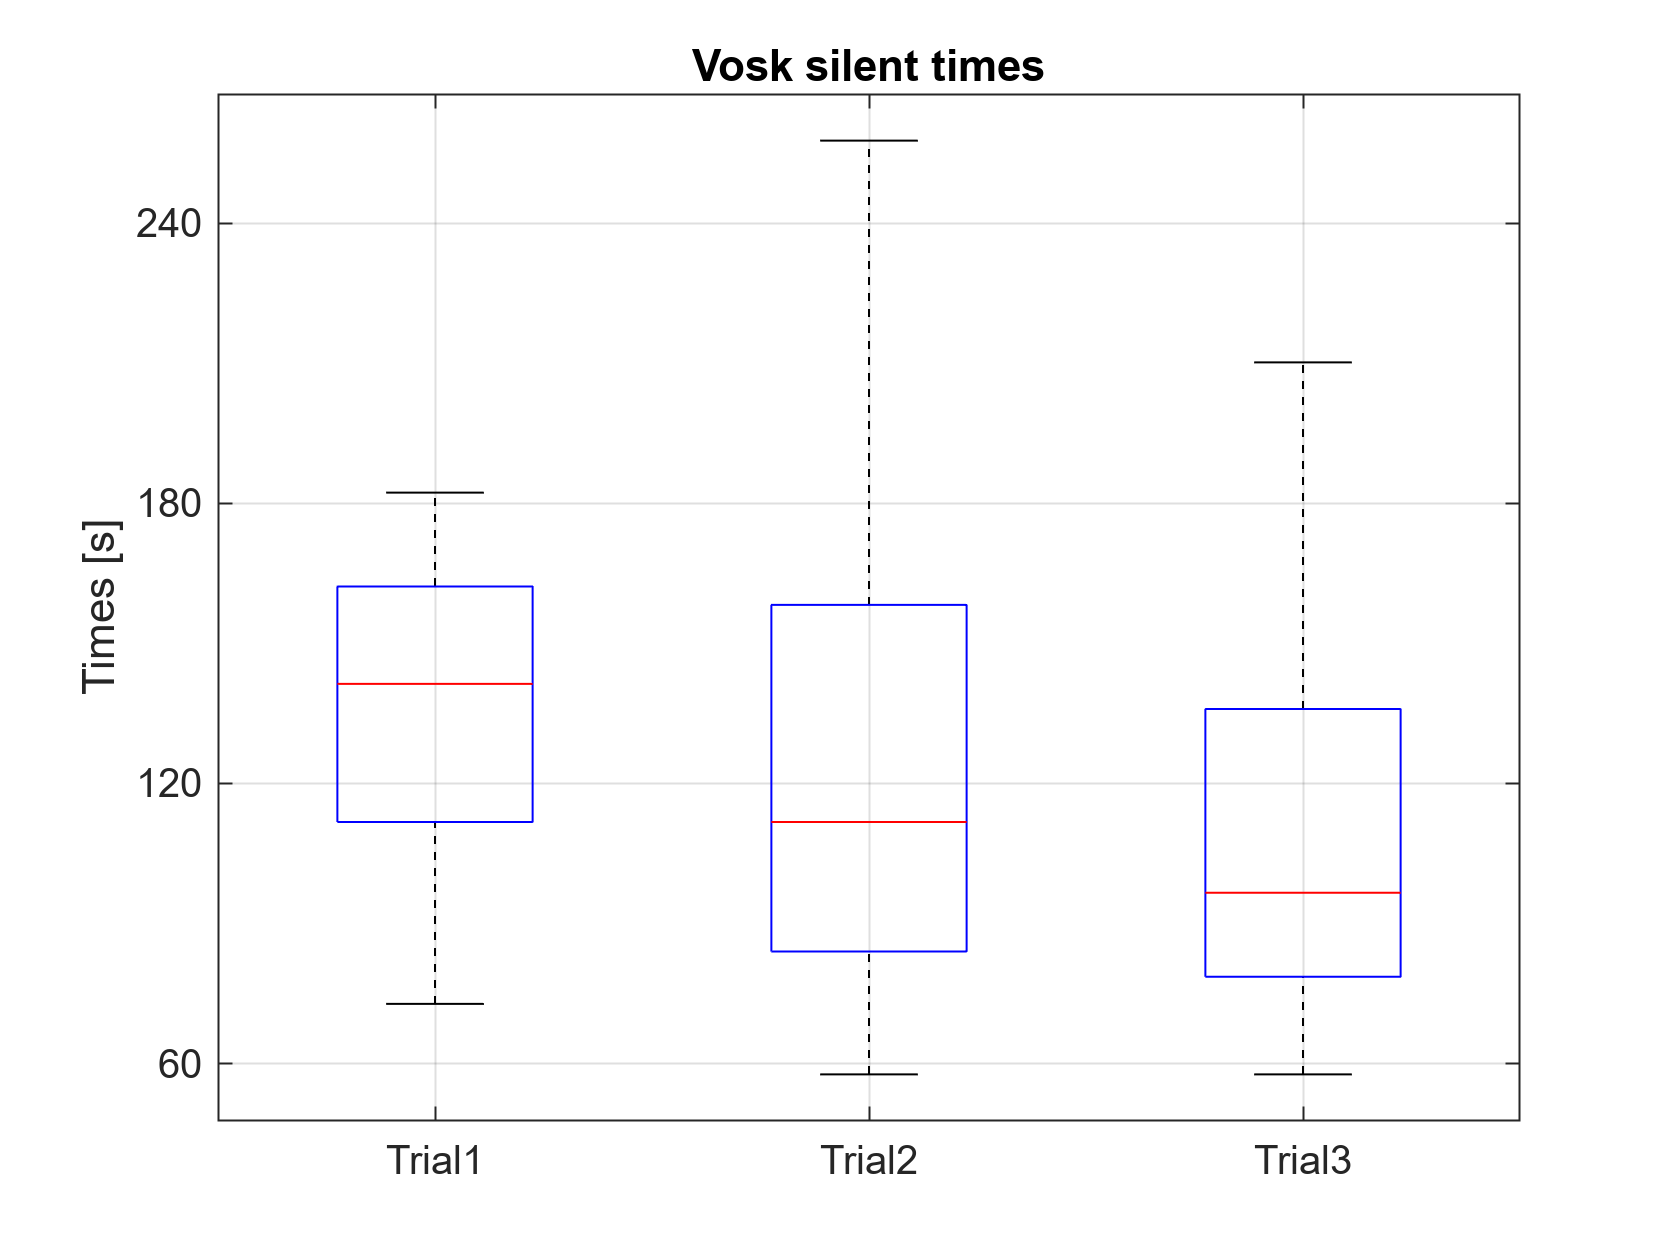

figure
boxplot([timesVS1, timesVS2, timesVS3], Labels={'Trial1','Trial2','Trial3'})
title('Vosk silent times')
ylabel('Times [s]')
yticks(0:60:700)
grid on

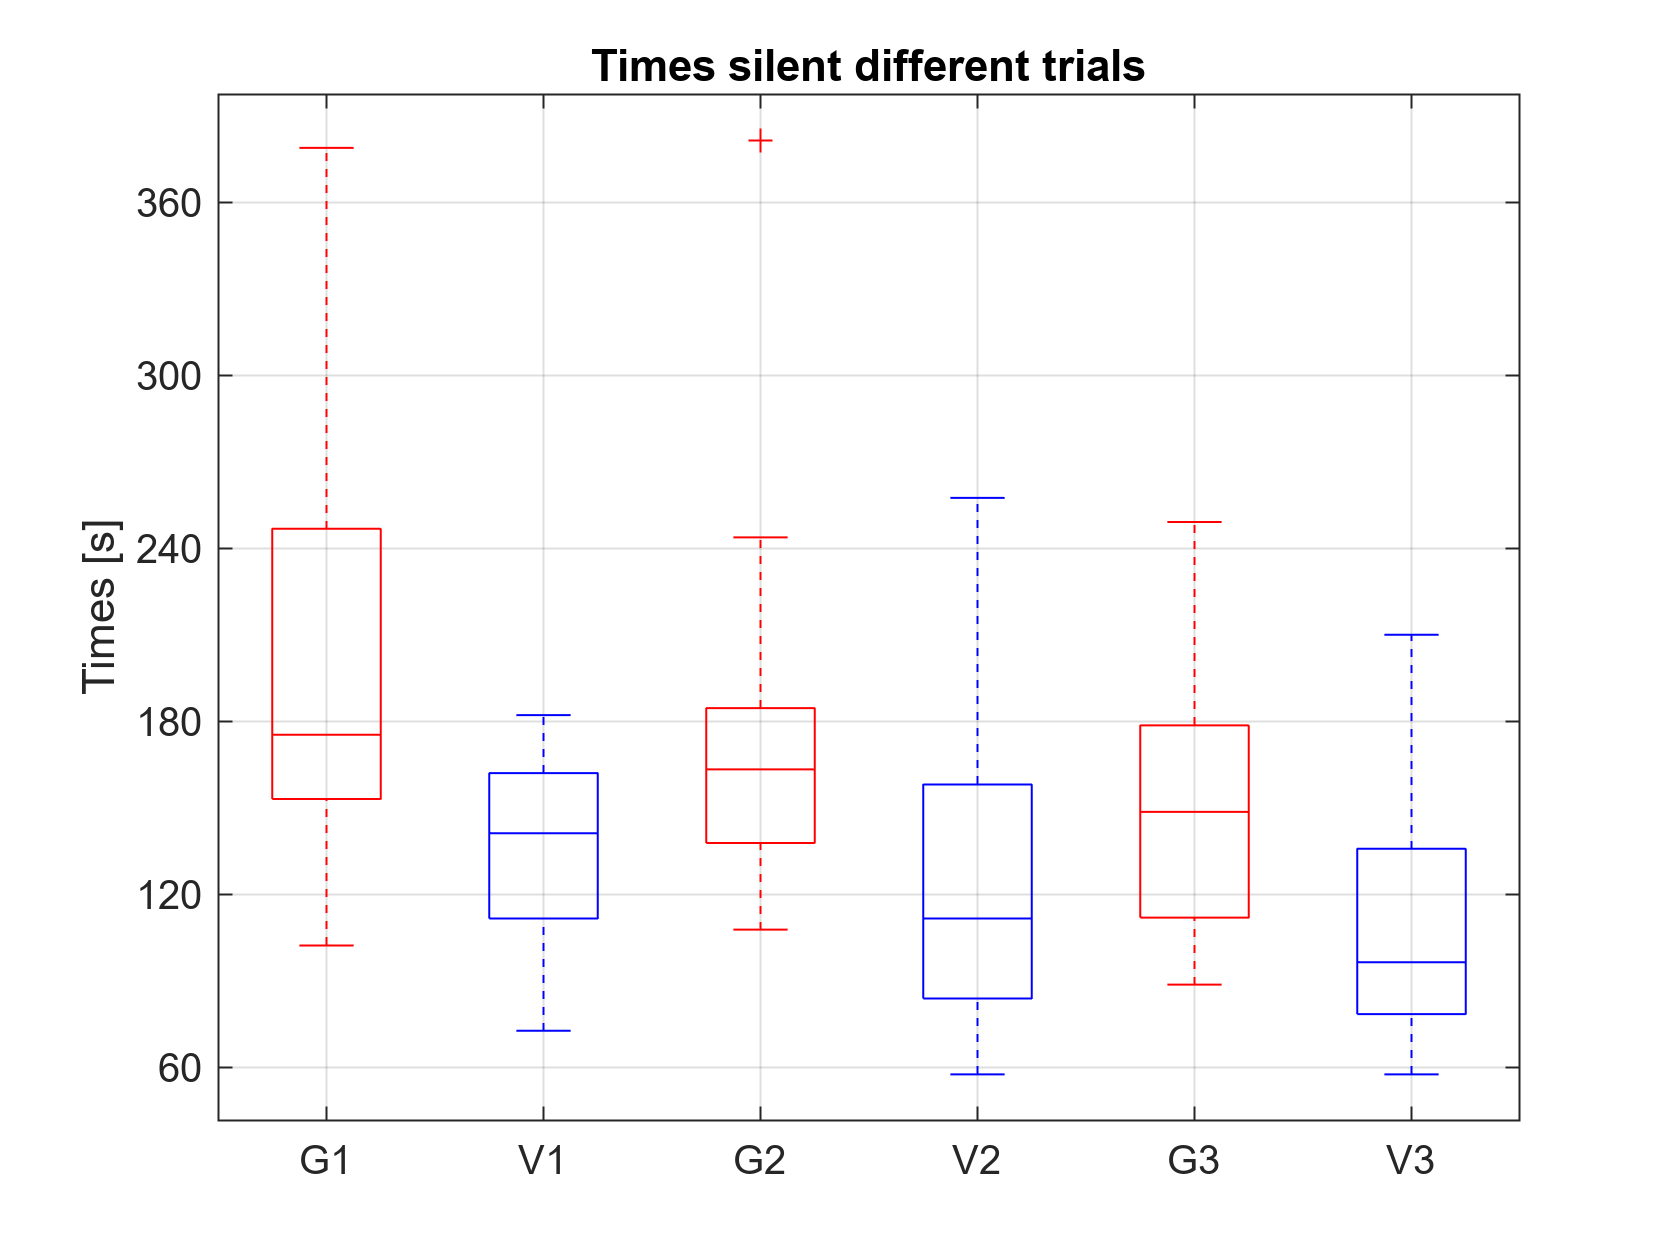



data = [timesGS1, timesVS1, timesGS2, timesVS2, timesGS3, timesVS3];
labels = {'G1','V1','G2','V2','G3','V3'};
colors = ['r','b','r','b','r','b'];

figure
boxplot(data, Labels=labels, Colors=colors)
title('Times silent different trials')
ylabel('Times [s]')
yticks(0:60:700)
grid on

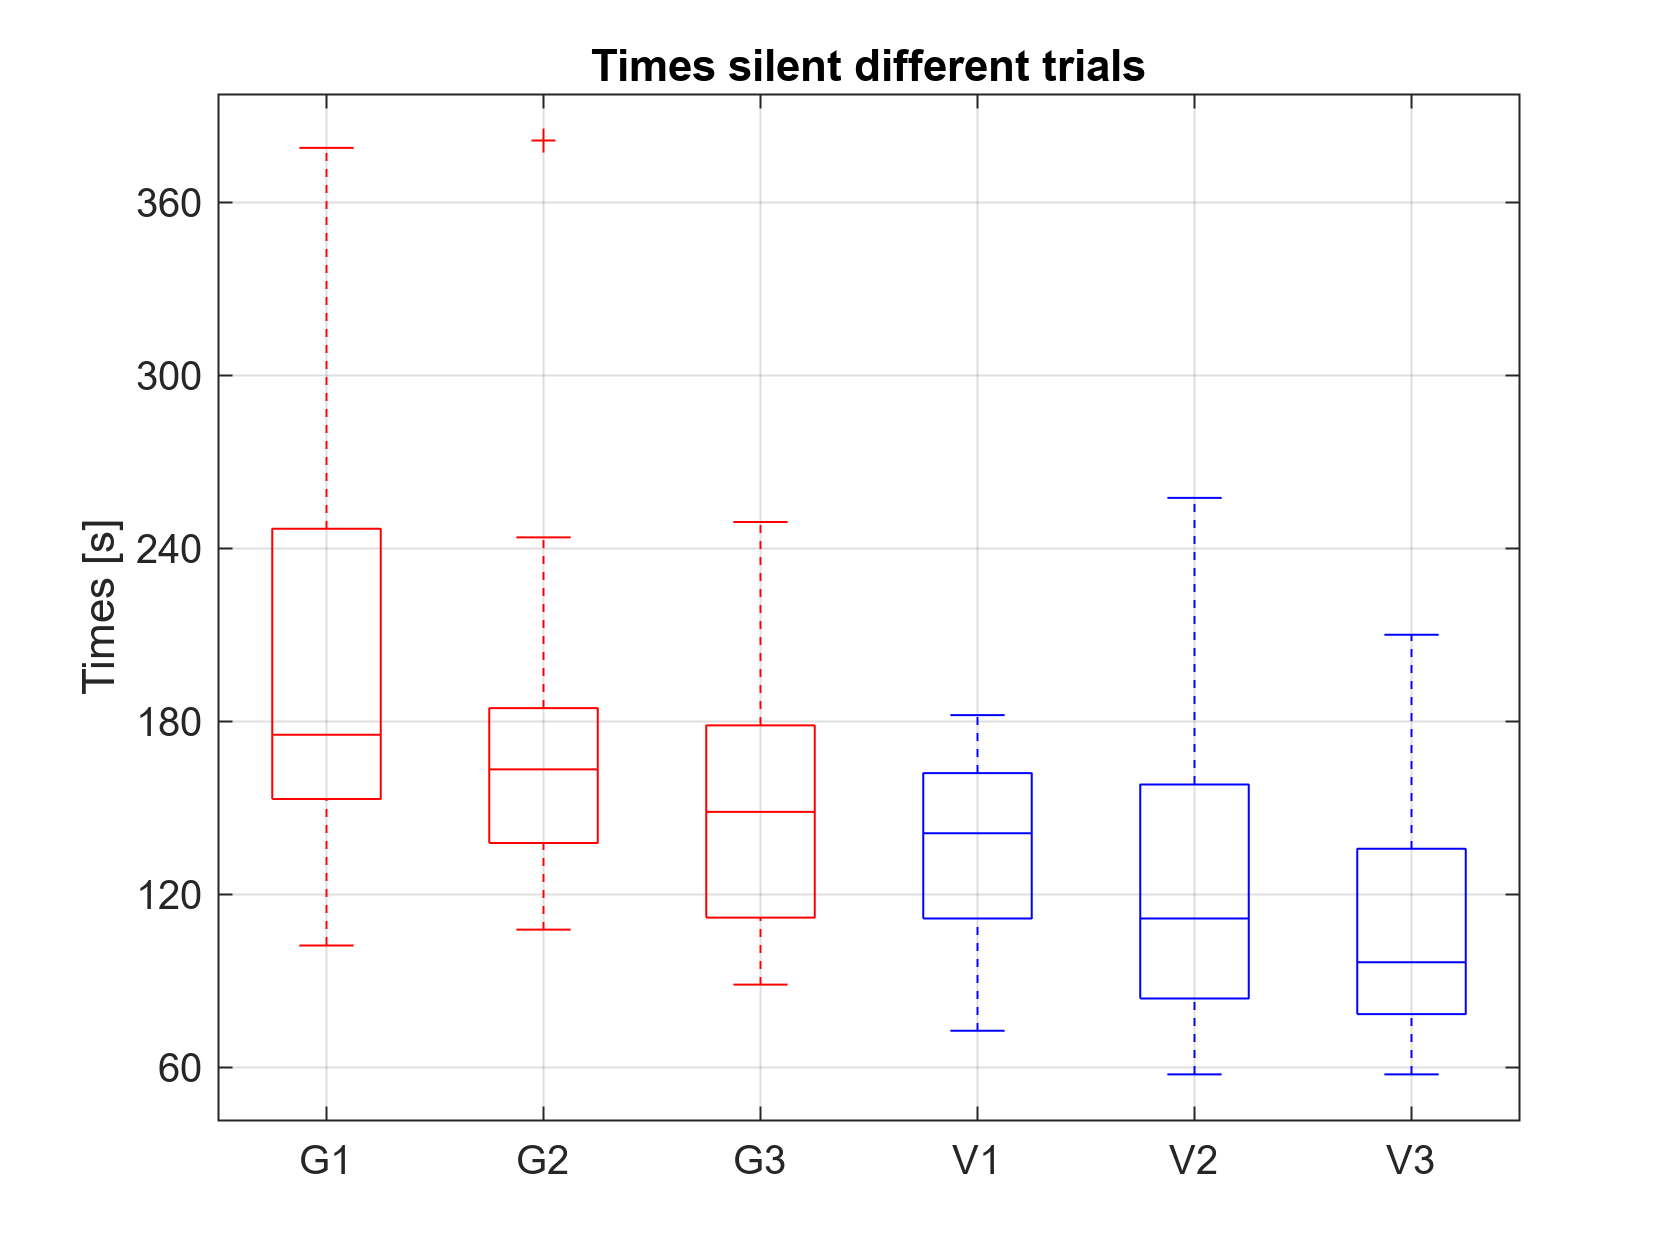



data = [timesGS1, timesGS2, timesGS3, timesVS1, timesVS2,  timesVS3];
labels = {'G1','G2','G3','V1','V2','V3'};
colors = ['r','r','r','b','b','b'];

figure
boxplot(data, Labels=labels, Colors=colors)
title('Times silent different trials')
ylabel('Times [s]')
yticks(0:60:700)


grid on

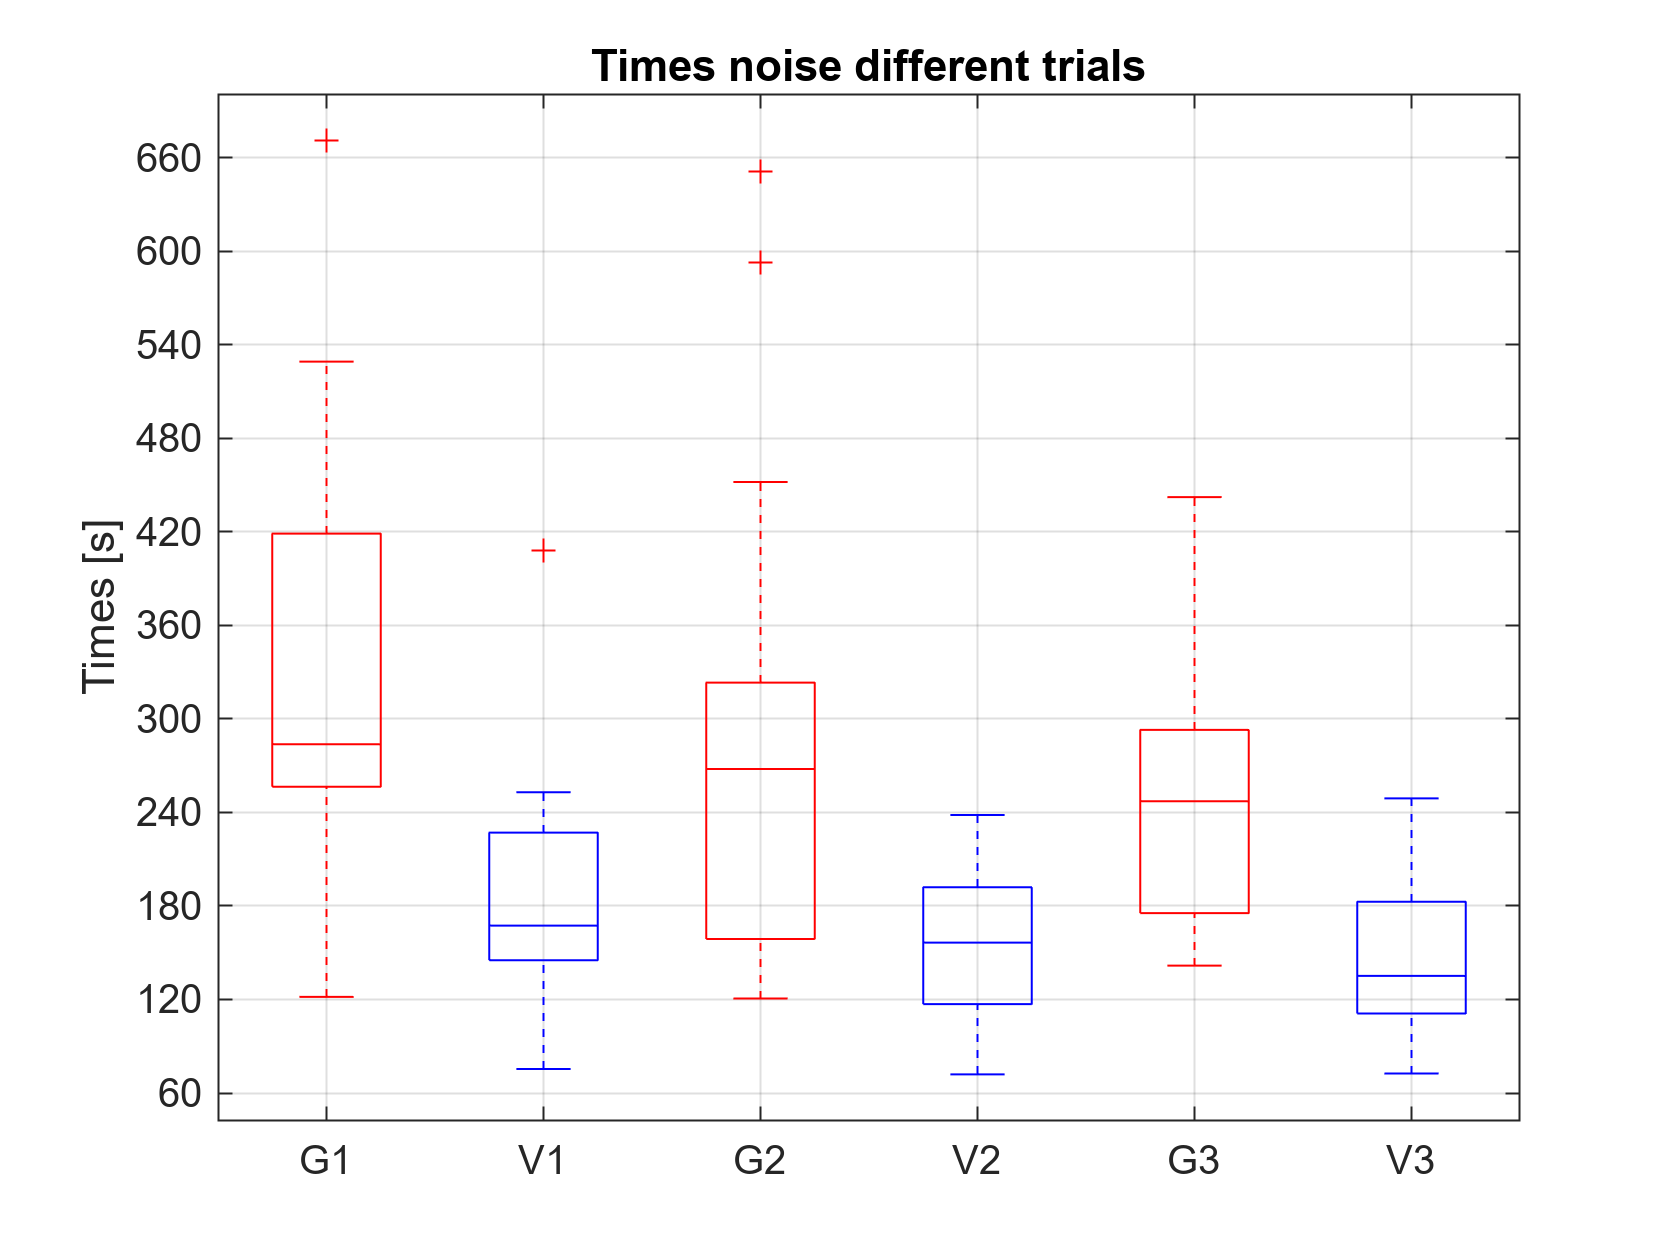


data = [timesGR1, timesVR1, timesGR2, timesVR2, timesGR3, timesVR3];
labels = {'G1','V1','G2','V2','G3','V3'};
colors = ['r','b','r','b','r','b'];

figure
boxplot(data, Labels=labels, Colors=colors)
title('Times noise different trials')
ylabel('Times [s]')
yticks(0:60:700)
grid on

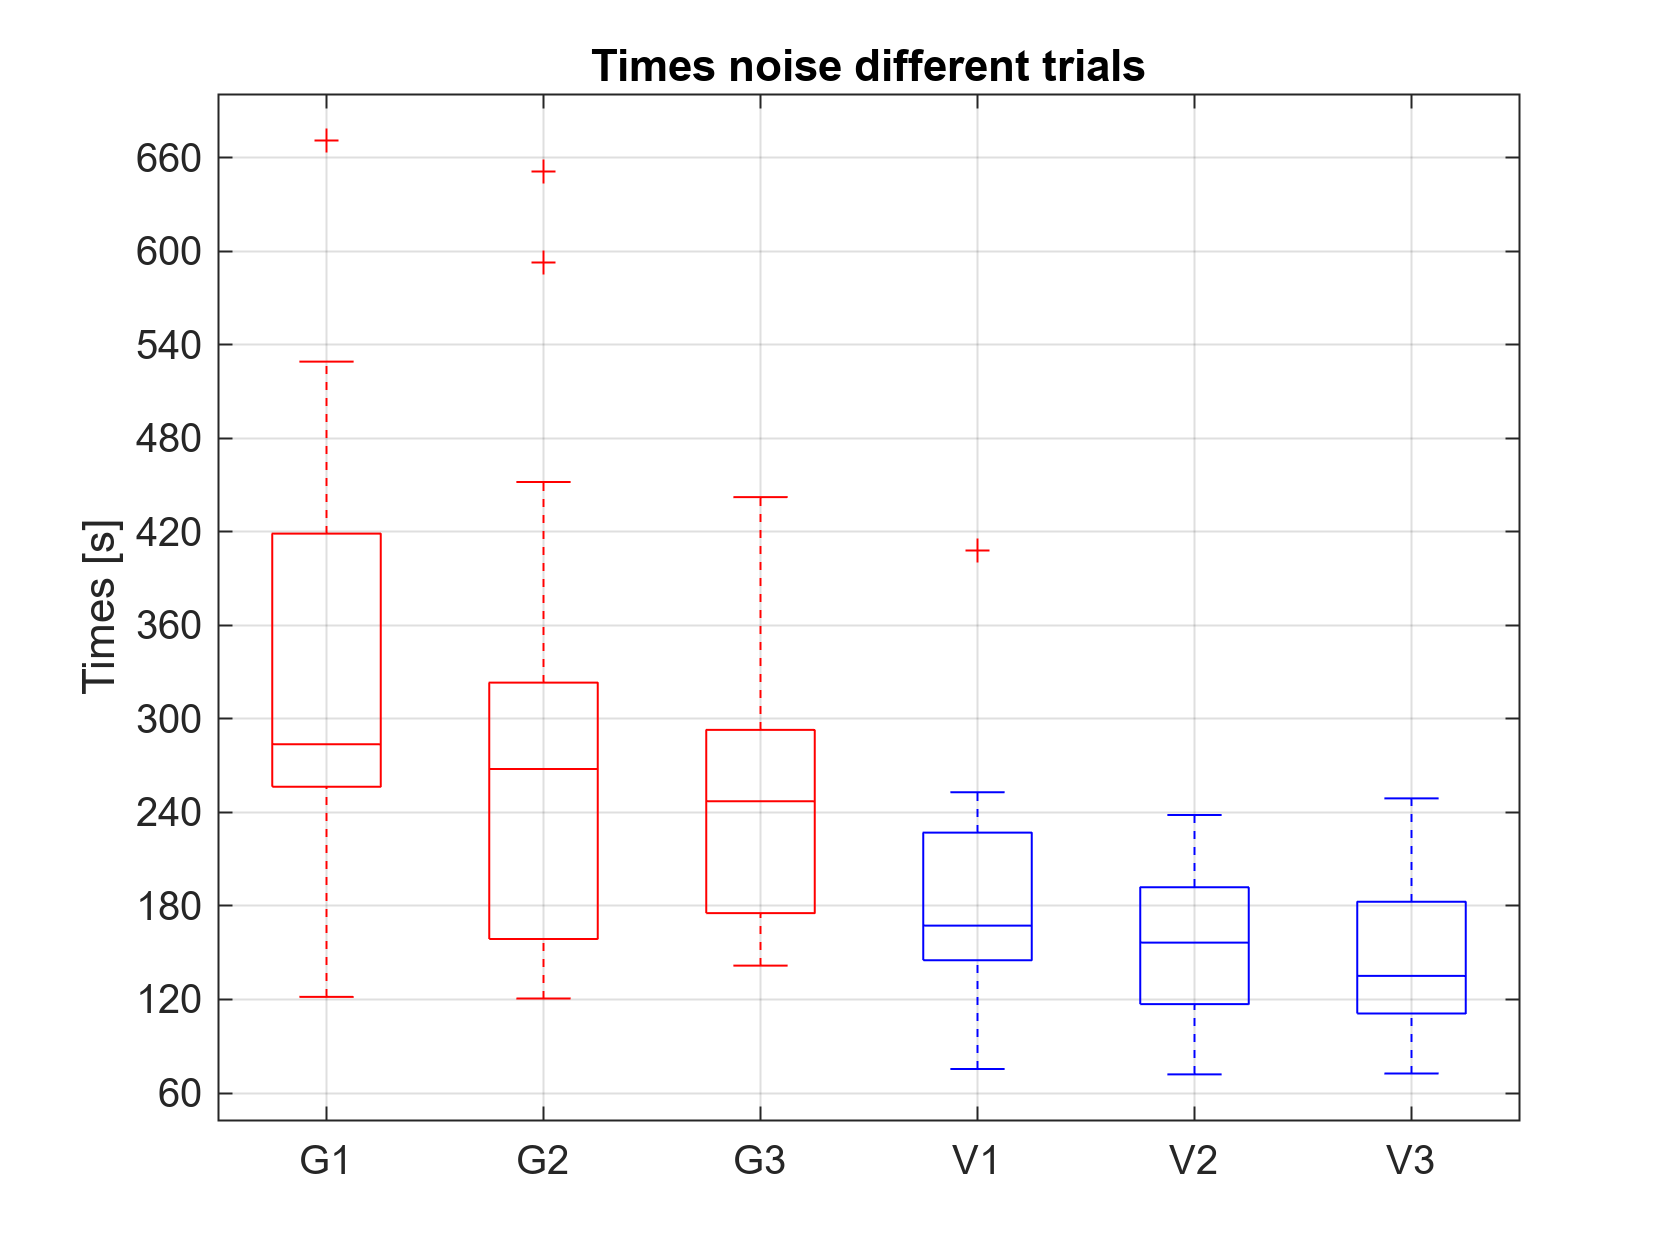

data = [timesGR1, timesGR2, timesGR3, timesVR1, timesVR2,  timesVR3];
labels = {'G1','G2','G3','V1','V2','V3'};
colors = ['r','r','r','b','b','b'];

figure
boxplot(data, Labels=labels, Colors=colors)
title('Times noise different trials')
ylabel('Times [s]')
yticks(0:60:700)
grid on


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CALULATING MEDIANS 

medianTGS1 = median(timesGS1);
medianTGS2 = median(timesGS2);
medianTGS3 = median(timesGS3);

medianTGR1 = median(timesGR1);
medianTGR2 = median(timesGR2);
medianTGR3 = median(timesGR3);


medianTVS1 = median(timesVS1);
medianTVS2 = median(timesVS2);
medianTVS3 = median(timesVS3);

medianTVR1 = median(timesVR1);
medianTVR2 = median(timesVR2);
medianTVR3 = median(timesVR3);


qTGS = quantile(timesGS, [0.25, 0.5, 0.75])

qTGS =   127.3500  168.1000  186.8500


qTGR = quantile(timesGR, [0.25, 0.5, 0.75])

qTGR =   175.3500  277.9500  313.1500



qTVS = quantile(timesVS, [0.25, 0.5, 0.75])

qTVS =    87.9500  116.0000  158.5000



qTVR = quantile(timesVR, [0.25, 0.5, 0.75])

qTVR =   116.6500  156.6500  204.9000


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CORRELATION SPEARMAN

[rho, p] = corr(iterGS, timesGS, 'type','Spearman')

rho = 0.8069

p = 7.0684e-15

[rho, p] =corr(iterVS, timesVS, 'type','Spearman')

rho = 0.9404

p = 7.5087e-29

[rho, p] = corr(iterGR, timesGR, 'type','Spearman')

rho = 0.9021

p = 7.7001e-23

[rho, p] = corr(iterVR, timesVR, 'type','Spearman')

rho = 0.9395

p = 1.1652e-28

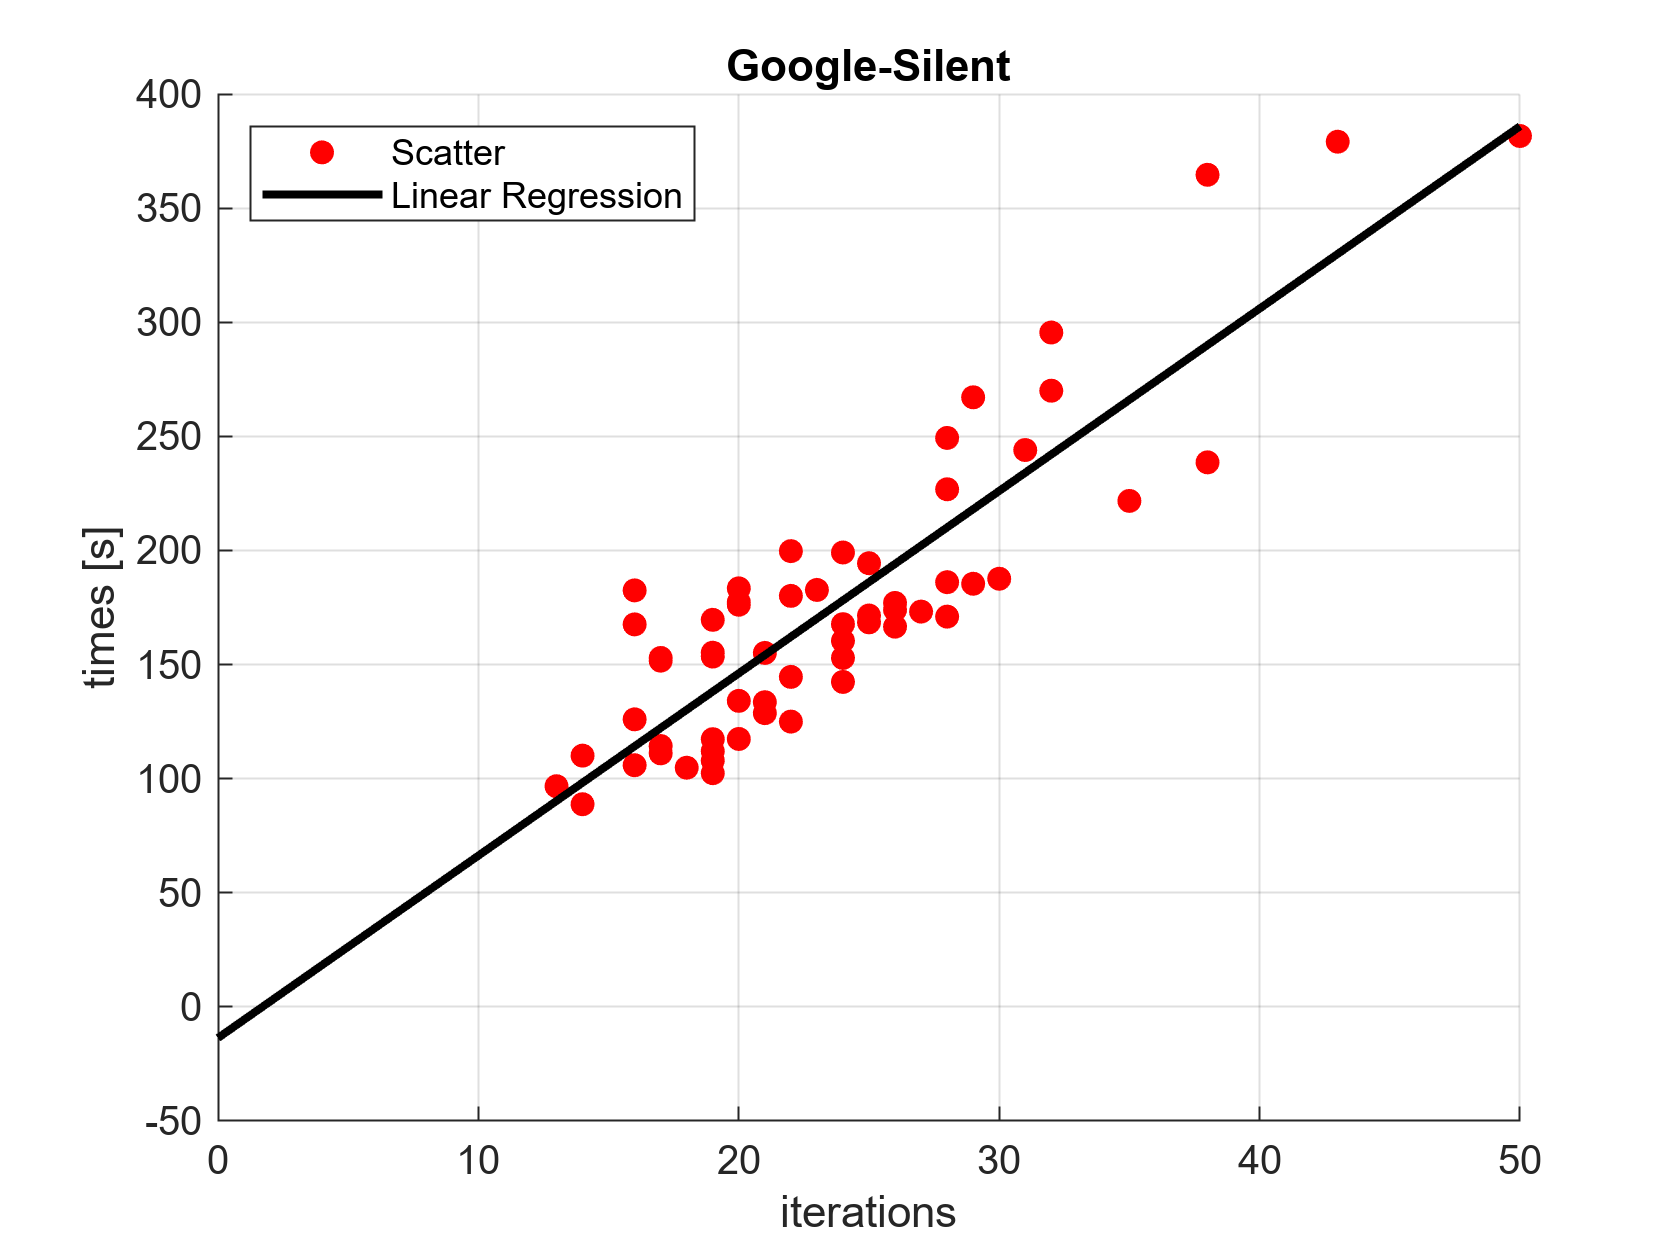

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5
% GENERATING LINEAR REGRESSION 

lin_TGS_IGS = polyfit(iterGS, timesGS, 1);
lin_TGR_IGR = polyfit(iterGR, timesGR, 1);
lin_TVS_IVS = polyfit(iterVS, timesVS, 1);
lin_TVR_IVR = polyfit(iterVR, timesVR, 1);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5
% CREATING SCATTERS WITH LINEAR REGRESSION 

xplot = linspace(0, max(iterGS), 1000);
figure
scatter(iterGS, timesGS, 'filled', 'r')
title('Google-Silent')
xlabel('iterations')
ylabel('times [s]')
hold on 
plot(xplot, polyval(lin_TGS_IGS, xplot), 'k', 'Linewidth',2)
legend('Scatter', 'Linear Regression', Location='northwest')
grid on

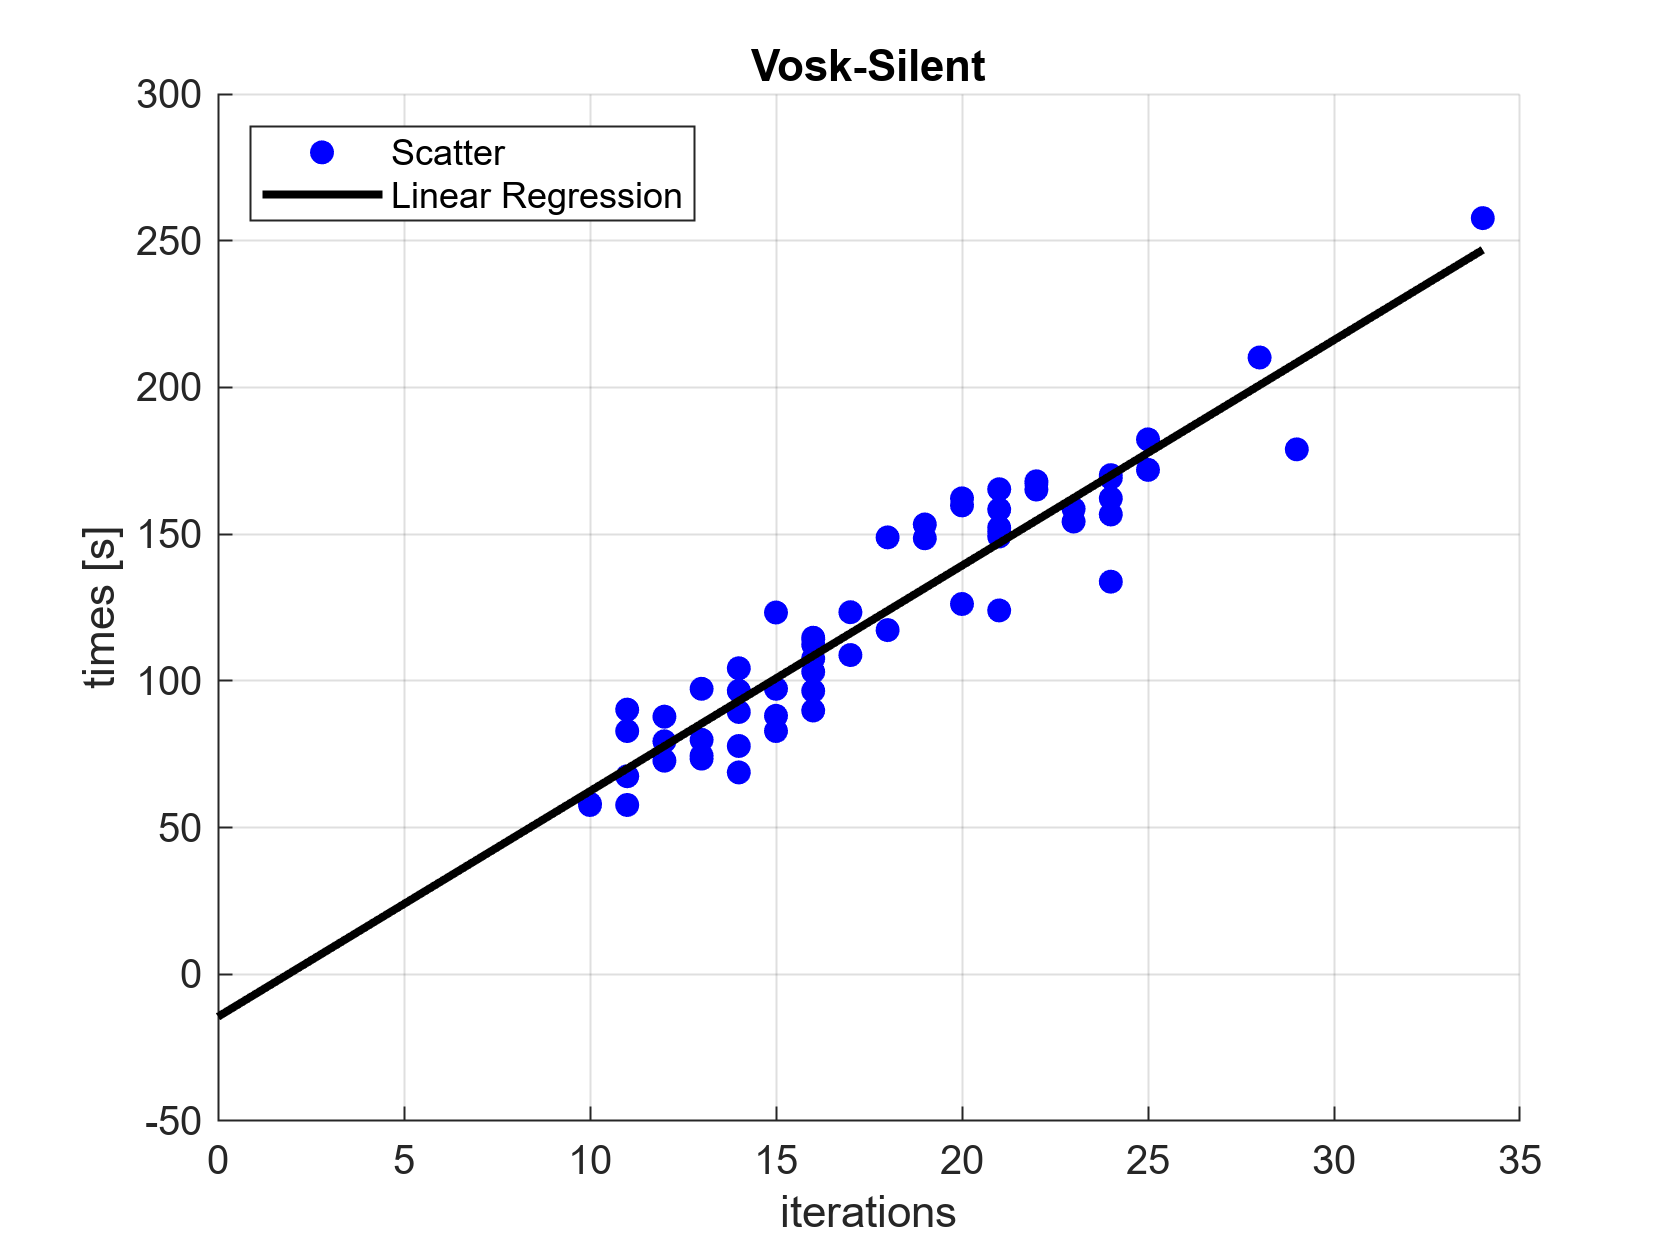



xplot = linspace(0, max(iterVS), 1000);
figure
scatter(iterVS, timesVS, 'filled', 'b')
title('Vosk-Silent')
xlabel('iterations')
ylabel('times [s]')
hold on 
plot(xplot, polyval(lin_TVS_IVS, xplot), 'k', 'Linewidth',2)
legend('Scatter', 'Linear Regression', Location='northwest')
grid on

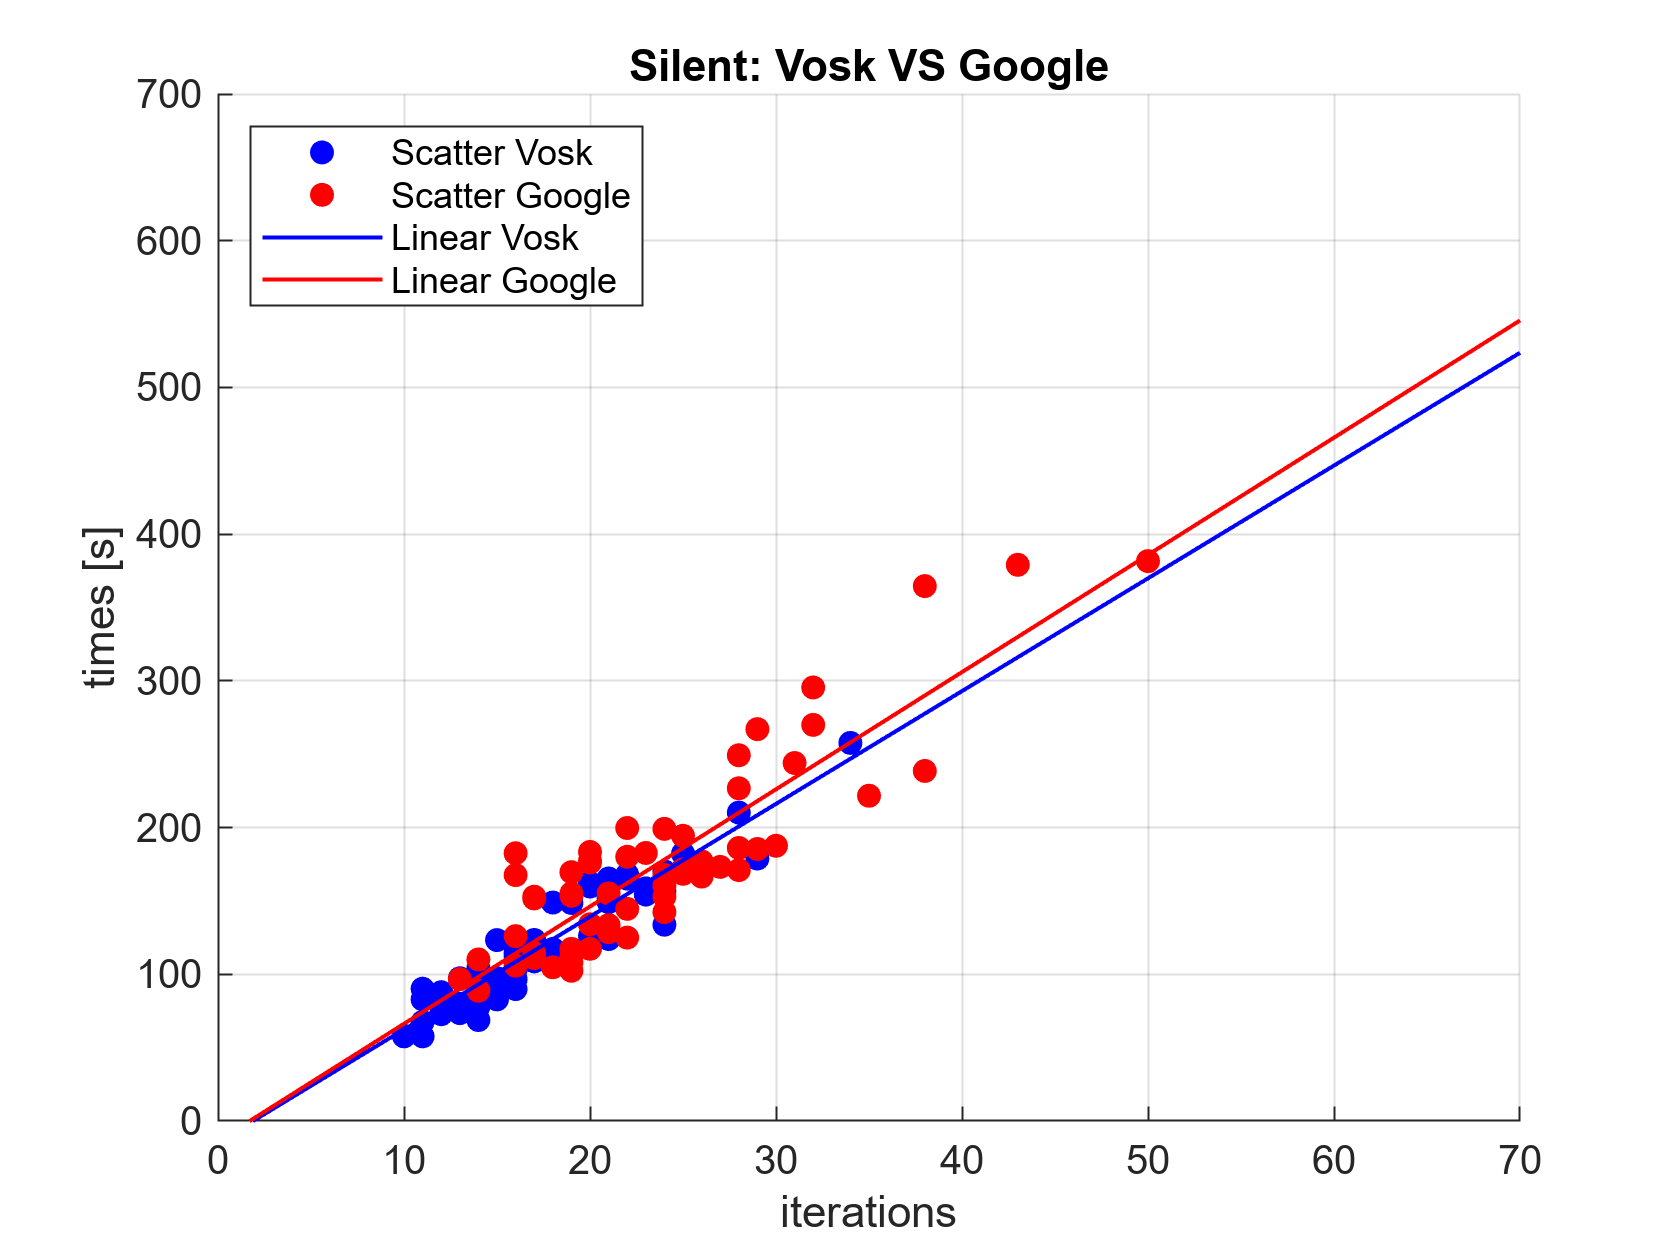


xplot= linspace(0, 70,1000);

figure
scatter(iterVS, timesVS, 'filled','b')
hold on
scatter(iterGS, timesGS, 'filled','r')
title('Silent: Vosk VS Google')
xlabel('iterations')
ylabel('times [s]')
hold on 
plot(xplot, polyval(lin_TVS_IVS, xplot), 'b', 'Linewidth',1)
hold on
plot(xplot, polyval(lin_TGS_IGS, xplot), 'r', 'Linewidth',1)
xlim([0 70])
ylim([0 700])

legend('Scatter Vosk','Scatter Google', 'Linear Vosk','Linear Google',  Location='northwest')
grid on

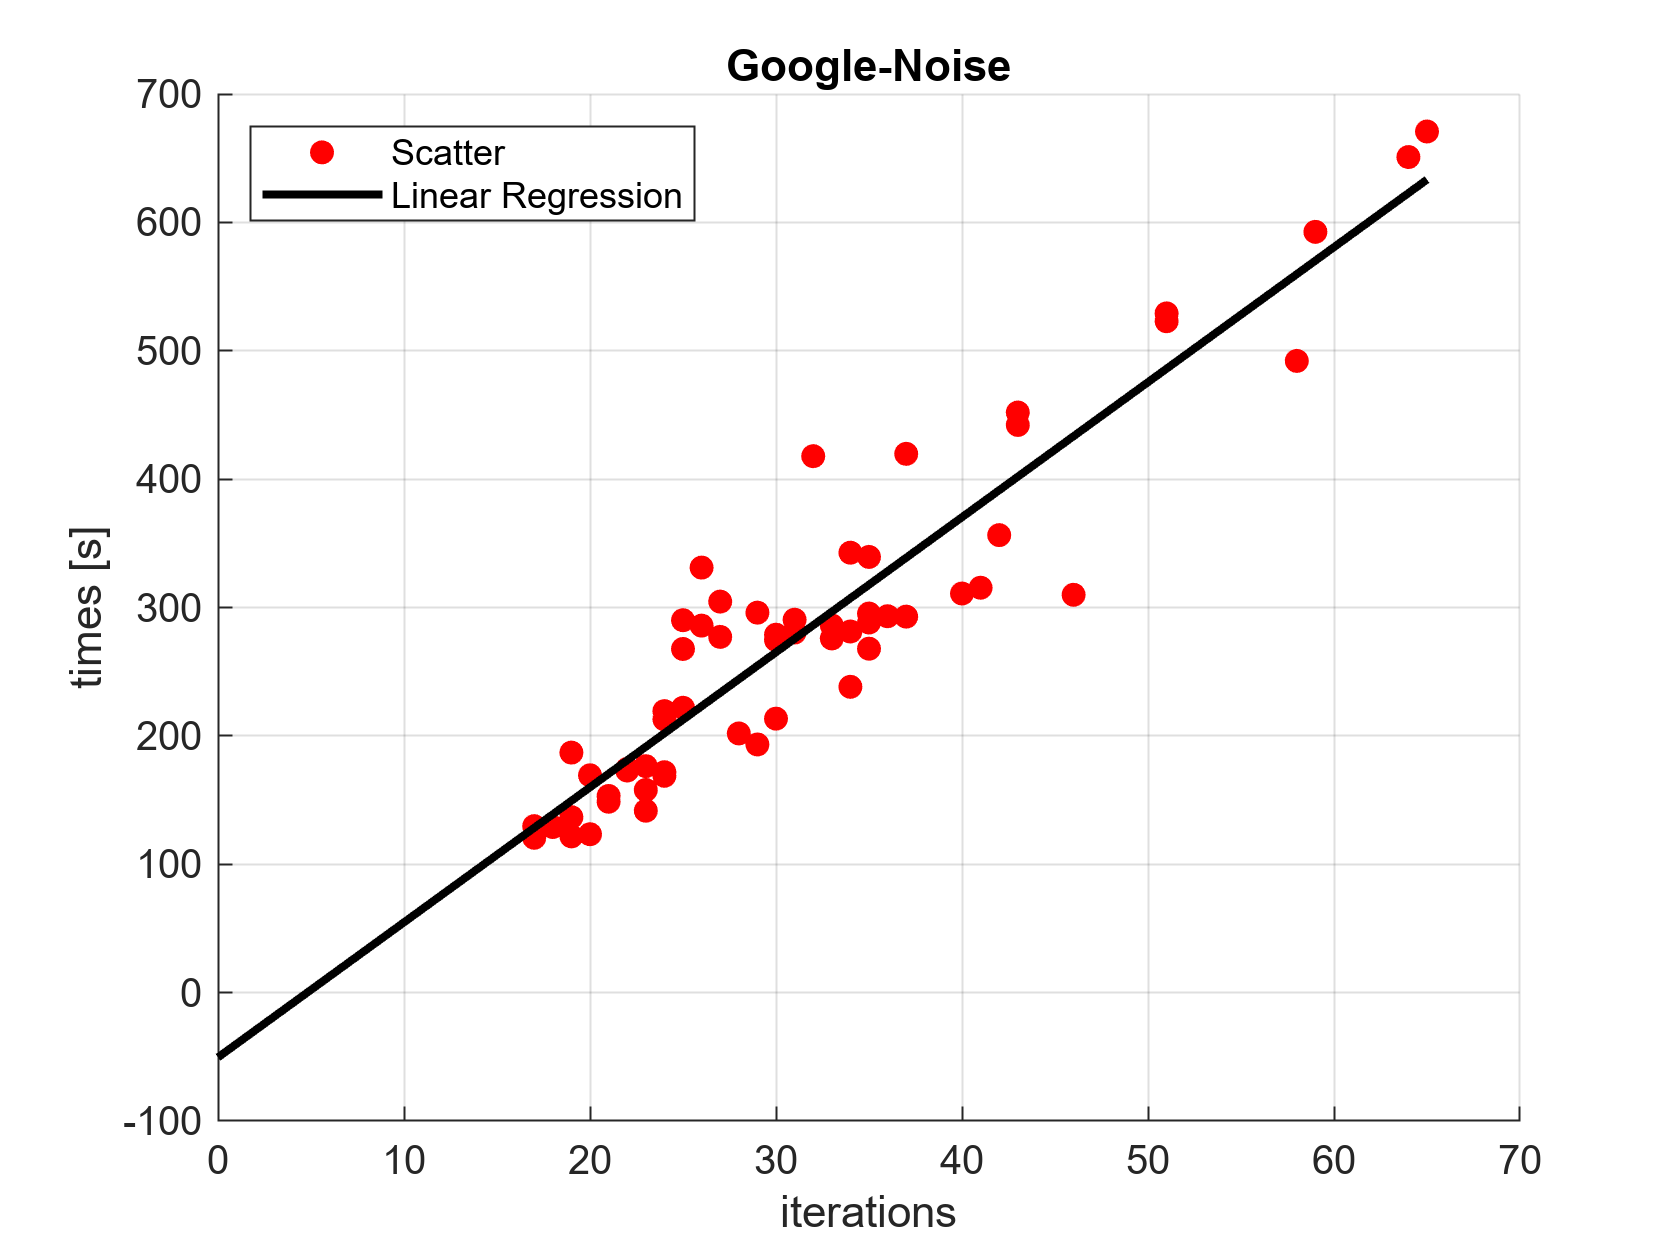



xplot = linspace(0, max(iterGR), 1000);
figure
scatter(iterGR, timesGR, 'filled', 'r')
title('Google-Noise')
xlabel('iterations')
ylabel('times [s]')
hold on 
plot(xplot, polyval(lin_TGR_IGR, xplot), 'k', 'Linewidth',2)
legend('Scatter', 'Linear Regression', Location='northwest')
grid on

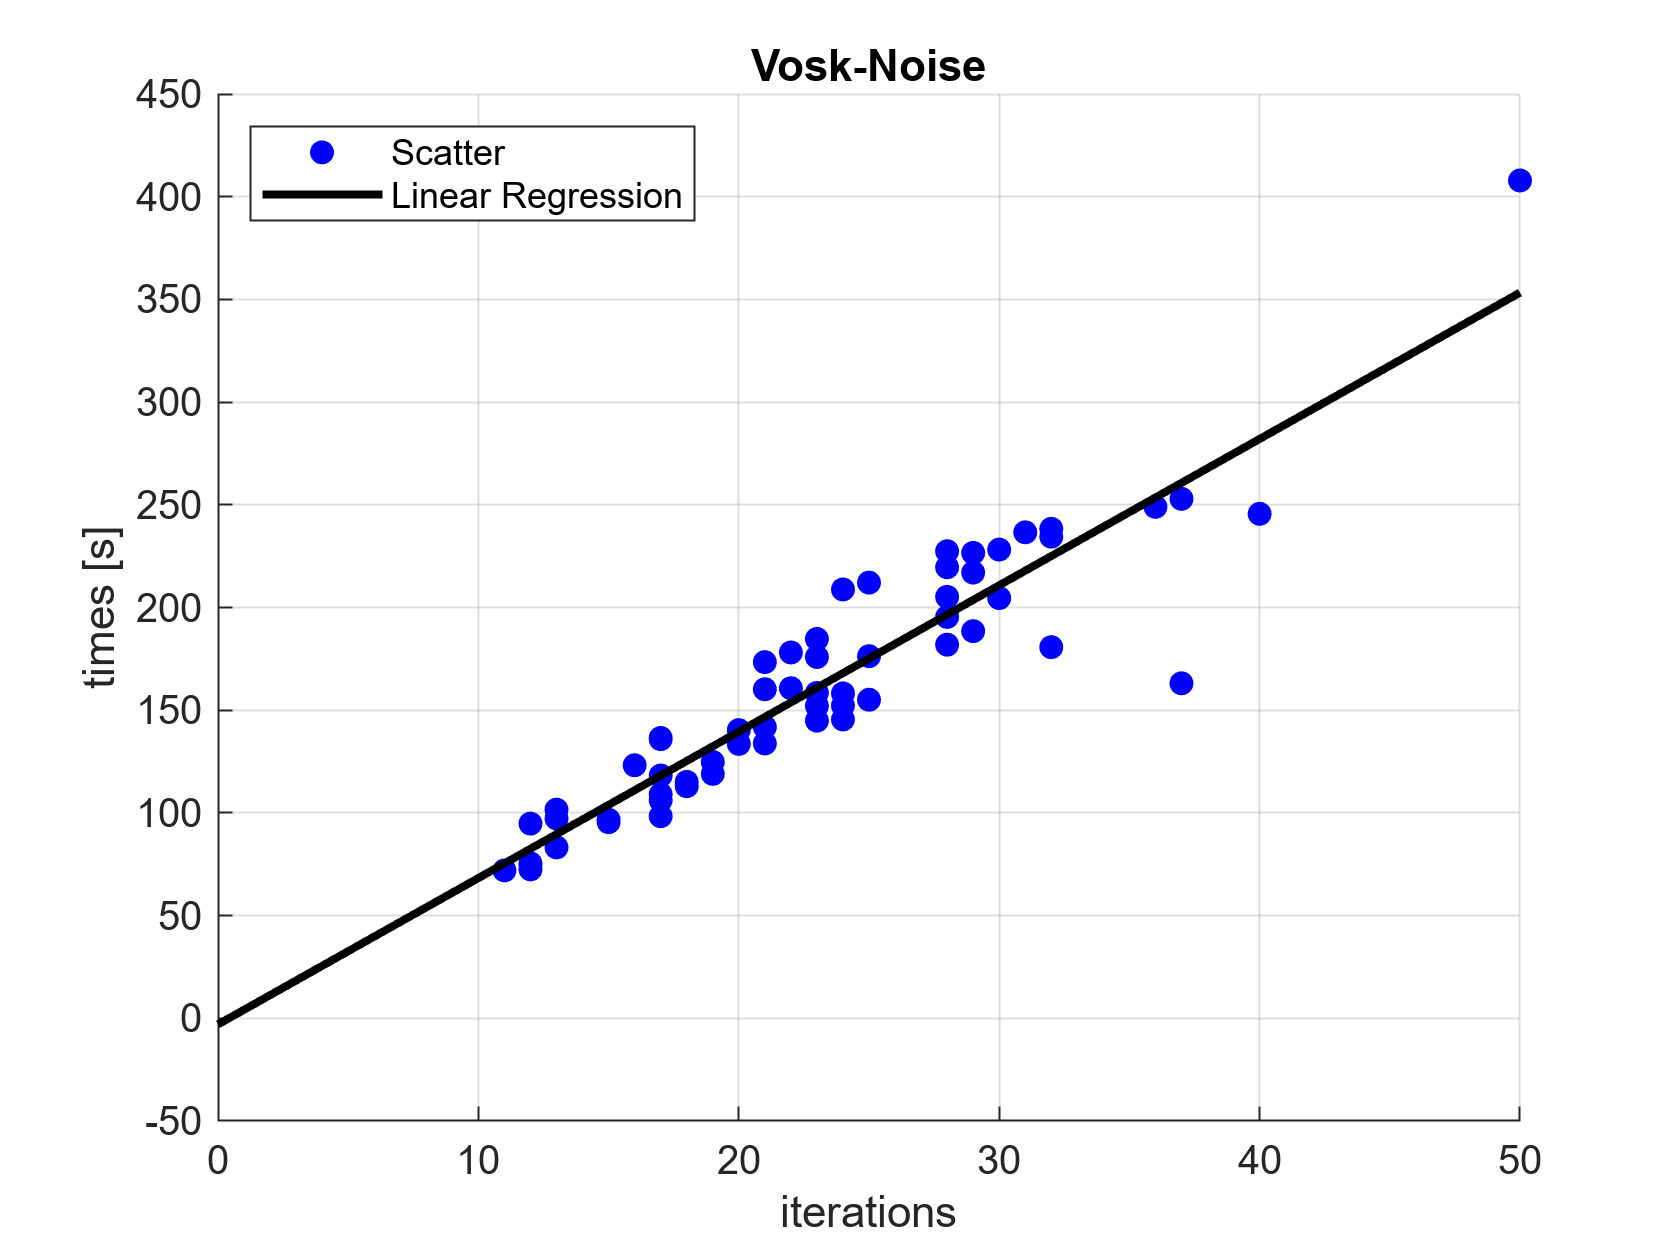

xplot = linspace(0, max(iterVR), 1000);
figure
scatter(iterVR, timesVR, 'filled', 'b')
title('Vosk-Noise')
xlabel('iterations')
ylabel('times [s]')
hold on 
plot(xplot, polyval(lin_TVR_IVR, xplot), 'k', 'Linewidth',2)
legend('Scatter', 'Linear Regression', Location='northwest')
grid on

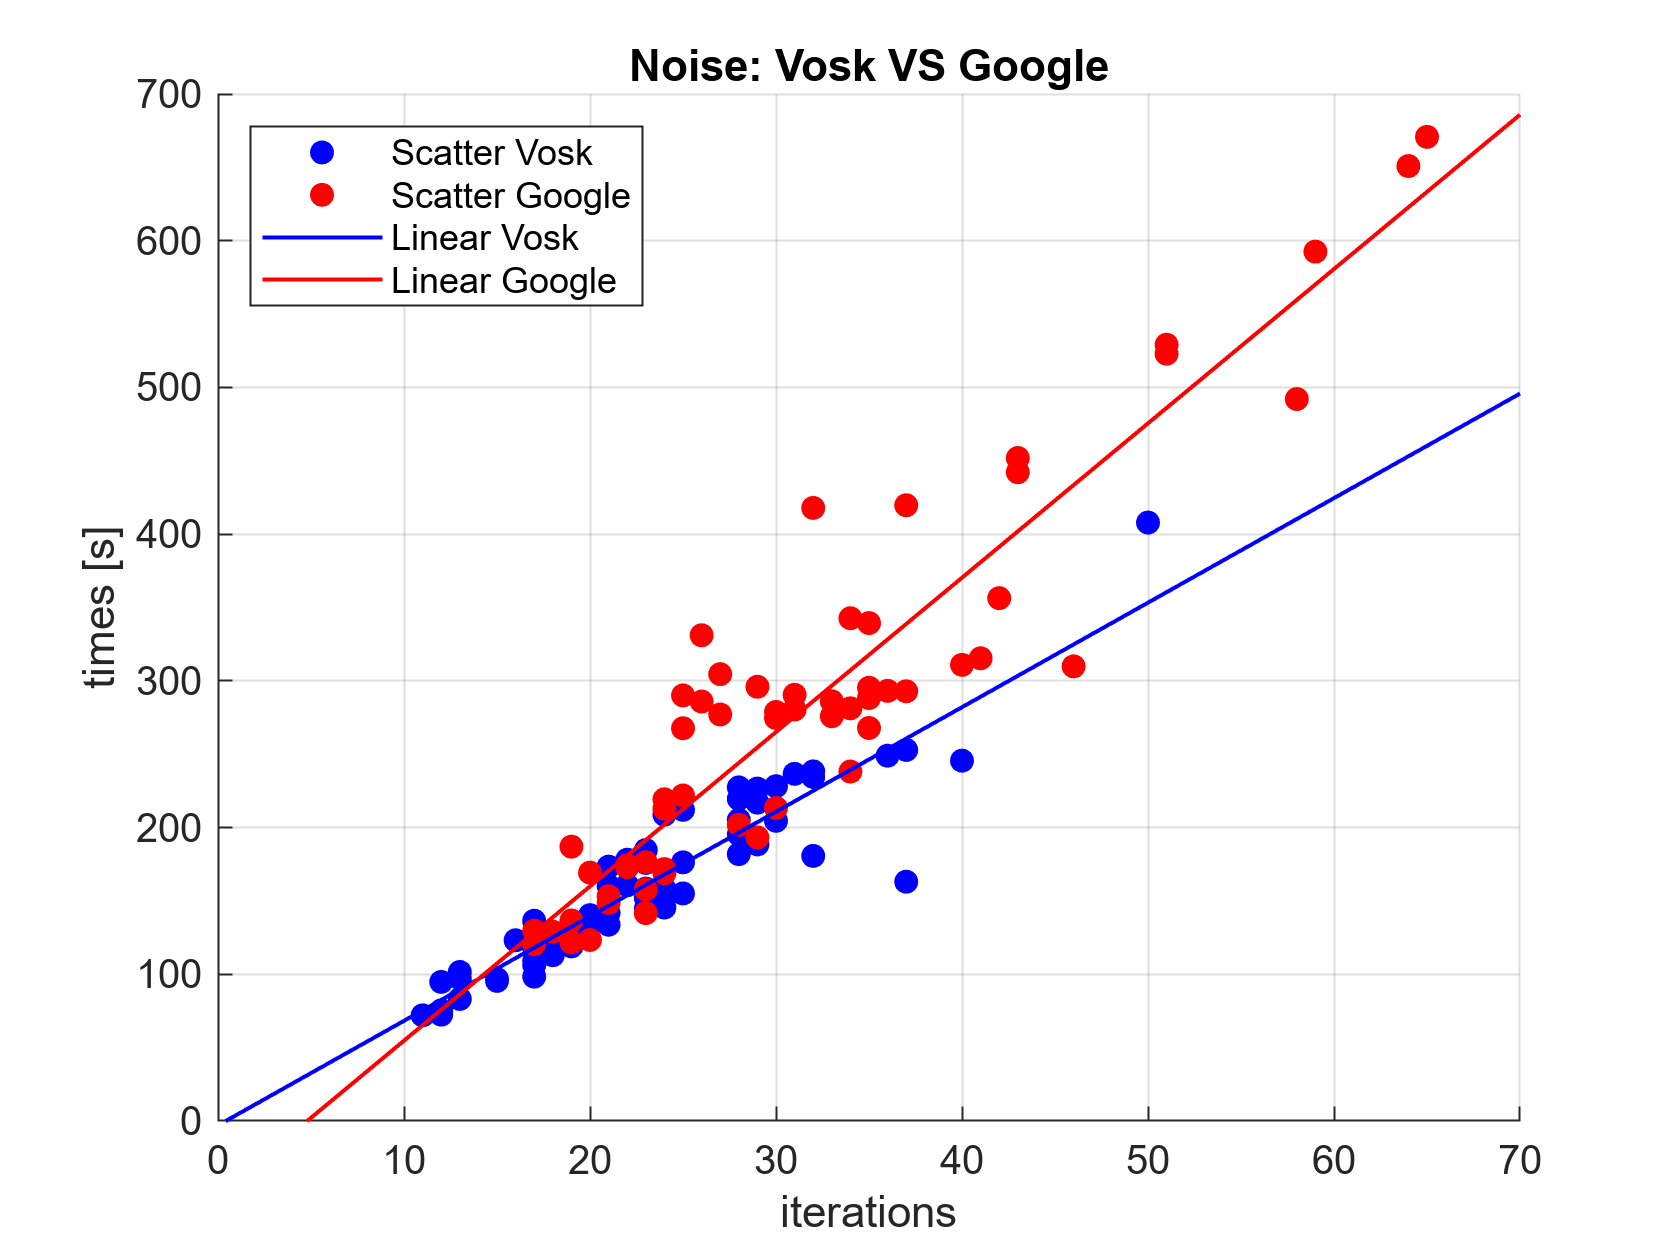


xplot= linspace(0, 70,1000);

figure
scatter(iterVR, timesVR, 'filled','b')
hold on
scatter(iterGR, timesGR, 'filled','r')
title('Noise: Vosk VS Google')
xlabel('iterations')
ylabel('times [s]')
hold on 
plot(xplot, polyval(lin_TVR_IVR, xplot), 'b', 'Linewidth',1)
hold on
plot(xplot, polyval(lin_TGR_IGR, xplot), 'r', 'Linewidth',1)
xlim([0 70])
ylim([0 700])

legend('Scatter Vosk','Scatter Google', 'Linear Vosk','Linear Google',  Location='northwest')
grid on

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% STATISTIC TEST 

% LEARNING VOSK 1-3

[p, h] = signrank(timesVS1, timesVS3)

p = 0.0032

h = logical
   1




% LEARNING GOOGLE 1-3

[p, h] = signrank(timesGS1, timesGS3)

p = 6.8061e-04

h = logical
   1


% SILENT: Google VS Vosk

[p, h] = signrank(timesGS, timesVS)    

p = 3.5619e-10

h = logical
   1


% NOISE: Google VS Vosk

[p, h] = signrank(timesGR, timesVR)    

p = 8.4181e-11

h = logical
   1



% GOOGLE: Silent VS Noise

[p, h] = signrank(timesGS, timesGR)     

p = 4.2397e-09

h = logical
   1


% VOSK: Silent VS Noise

[p, h] = signrank(timesVS, timesVR)  

p = 6.8122e-08

h = logical
   1


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% LEARNING TREND - GOOGLE

medians_TGS = [medianTGS1, medianTGS2, medianTGS3]

medians_TGS =   175.5000  163.5000  148.7500



decrease_median_perc_TGS =  (medians_TGS(2:end)-medians_TGS(1:end-1))./medians_TGS(1:end-1)*100

decrease_median_perc_TGS =    -6.8376   -9.0214


% LEARNING TREND - VOSK

medians_TVS = [medianTVS1, medianTVS2, medianTVS3]

medians_TVS =   141.3500  111.7500   96.6000



decrease_median_perc_TVS =  (medians_TVS(2:end)-medians_TVS(1:end-1))./medians_TVS(1:end-1)*100

decrease_median_perc_TVS =   -20.9409  -13.5570


% This function return the vector without all the Nan and zeros element 


function vector_new = depurate(vector)

    vector_wto_zeros = vector( vector~=0 );
    vector_new = vector_wto_zeros( ~isnan(vector_wto_zeros));

end
